# Liniowe systemy dynamiczne: obserwowalność, reprezentacje kanoniczne, obserwator Luenbergera

Krzysztof Arent

2024

## laboratorium

#### imię i nazwisko studenta:  Aleksander Łyskawa, Kacper Karkosz

### Zadanie 1

Rozważmy reprezentację liniowego systemu dynamicznego ze zmiennymi stanu


$$\dot{x}=A x + B u \\
y=C x$$
 
$$\quad (1)$$


Rozwiązanie (1) ma postać:


$$y(t,u,x_0)=C e^{A t} x_0 + \int_0^t C e^{A(t-\tau)} B u(\tau) d \tau.$$


Mówimy, że $x_{0,1}, x_{0,2} \in \mathbb{R}^n, x_{0,1}\neq x_{0,2}$, są *nierozróżnialne* wtedy i tylko wtedy gdy $y(t,u,x_{0,1})-y(t,u,x_{0,2}) = 0 ~\forall t$. 

Mówimy, że system (1) jest *obserwowalny* wtedy i tylko wtedy gdy każda para $x_{0,1}, x_{0,2} \in \mathbb{R}^n, x_{0,1}\neq x_{0,2}$ jest rozróżnialna. 

Zauważmy, że $y(t,u,x_{0,1})-y(t,u,x_{0,2}) =C e^{A t} (x_{0,1}-x_{0,2})$. Innymi słowy $y(t,u,x_{0,1})-y(t,u,x_{0,2}) = 0 ~\forall t$ wtedy i tylko wtedy gdy $x_{0,1}-x_{0,2} \in  \ker (C e^{A t}) ~\forall t \geq 0$. 

Okazuje się, że $\ker (C e^{A t}) = \ker \mathcal{O}$, gdzie  $\mathcal{O}=$$\left\lbrack \begin{array}{c}
C\\
C\;A\\
\vdots \\
C\;A^{n-1} 
\end{array}\right\rbrack$. W konsekwencji, system (1) jest obserwowalny wtedy i tylko wtedy gdy $\mbox{rank} \mathcal{O}=n$.

Jeżeli system (1) jest nieobserwowalny, tzn. istnieją $x_{0,1}, x_{0,2} \in \mathbb{R}^n$ które są nierozróżnialne, to dla tych stanów $y(t,u,x_{0,1})=y(t,u,x_{0,2}) $ choć $x(t,u,x_{0,1}) \neq x(t,u,x_{0,2}) $. Innymi słowy, jeżeli system (1) nie jest obserwowalny to jednej parze trajektorii w czasie wejście/wyjście może odpowiadać więcej niż jedna trajektoria w przestrzeni stanu. A to oznacza, że w przypadku systemu nieobserwowalnego nie można zrekonstruować trajektorii stanu $x$ w czasie na podstawie obserwacji trajektorii $u, ~y$ w czasie.

Celem tego zadania jest nabycie pewnych intuicji dotyczących powyższego spostrzeżenia.

Niech $A=$$\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-a_0  & -a_1  & -a_2 
\end{array}\right\rbrack$, $B=$$\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$, $C=$$\left\lbrack \begin{array}{ccc}
c_1  & c_2  & c_3 
\end{array}\right\rbrack \ldotp$ Przyąć $a_0=6, ~a_1=11, ~a_2=6$, $c_0=2, ~c_1=3, ~c_2=1$, $u(t)=\cos(\frac{1}{3}t)$.  Wyznaczyć macierz obserwowalności Kalmana $\mathcal{O}$. Zbadać czy rozważany system jest obserwowalny. W przypadku gdyby system okazał się nieobserwowalny wyliczyć $\dim \ker \mathcal{O}$ oraz wersory rozpinające $\ker \mathcal{O}$. Wybrać jakieś $x_{0,1}, x_{0,2} \in \ker \mathcal{O}, x_{0,1}\neq x_{0,2}$ (o ile to możliwe) i wyznaczyć numerycznie$x(t,u,x_{0,1}), ~ x(t,u,x_{0,2}) $ oraz $y(t,u,x_{0,1}), ~y(t,u,x_{0,2}) $. 

Powyższe zadanie można zrealizować w sposób następujący:

clear all
close all

% macierze systemu (1)
A=[0,1,0; 0,0,1;-6,-11,-6]

A =      0     1     0
     0     0     1
    -6   -11    -6


B=[0;0;1]

B =      0
     0
     1


C=[2,3,1]

C =      2     3     1


D=0

D = 0

% obiekt reprezentujący system dynamiczny ze zmiennymi stanu wyznaczony
% przez macierze A, B, C, D
systemDynamiczny=ss(A,B,C,D);
% macierz obserwowalności Kalmana dla systemDynamiczny
O=obsv(systemDynamiczny)

O =      2     3     1
    -6    -9    -3
    18    27     9


% macierz złożona z wektorów ortonormalnych rozpinających ker O
nO=null(O)

nO =     0.8452    0.0000
   -0.5071   -0.3162
   -0.1690    0.9487


% wyznaczanie stanów początkowych, których wartości pochodzą z ker O.
if ~isempty(nO)
    disp('systemDynamiczny nie jest obserwowalny')
    x01=sum( (nO.*rand(1,size(nO,2)))' )'
    x02=sum( (nO.*rand(1,size(nO,2)))' )'
    while norm(x01-x02) < 1e-10  % tutaj zapewniamy, że x01~=x02
        x01=sum( (nO.*rand(1,size(nO,2)))' )'
        x02=sum( (nO.*rand(1,size(nO,2)))' )'
    end
    T=[0,20];
    % definicja sygnału wejściowego
    [u_sin,T_sin] = gensig("sine",2*pi*3,T(end));
    % symulacje systemDynamiczny dla dwóch stanów początkowych: x01 i x02
    [y1, Tout1, x1]=lsim(systemDynamiczny,u_sin,T_sin, x01);
    [y2, Tout2, x2]=lsim(systemDynamiczny,u_sin,T_sin, x02);
    if all(abs(y1-y2) < 1e-14)
        disp('y1==y2  :)')
    else
        disp('y1~=y2  :(')
    end
    f{1}=figure(1)
    plot(T_sin, u_sin, 'blue')
    hold on
    plot(T_sin, u_sin, 'red')
    xlabel('t'), ylabel('u_1, u_2')
    hold off
     
    f{2}=figure(2)
    plot(Tout1, y1, 'blue')
    hold on
    plot(Tout2, y2, 'red')
    xlabel('t'), ylabel('y_1, y_2')
    hold off
    f{3}=figure(3)
    plot(Tout1, x1, 'blue')
    hold on
    plot(Tout2, x2, 'red')
    xlabel('t'), ylabel('x_1, x_2')
    hold off
else
    disp('systemDynamiczny jest obserwowalny')
end

systemDynamiczny nie jest obserwowalny


x01 =     0.1322
   -0.3499
    0.7852


x02 =     0.5449
   -0.4459
    0.2480


y1==y2  :)


f = 1×1 cell array
    {1×1 Figure}


f = 1×2 cell array
    {1×1 Figure}    {1×1 Figure}


f = 1×3 cell array
    {1×1 Figure}    {1×1 Figure}    {1×1 Figure}


Czy w przypadku rozważanego systemu, z faktu, że $(y_1, x_1, u_1) \mbox{ oraz } (y_2, x_2, u_2)$ są rozwiązaniem (1) oraz faktu że $u_1 \equiv u_2 \mbox{ oraz } y_1 \equiv y_2$ wynika, że $x_1 \equiv x_2$ ? Uzasadnij odpowiedź. Jakie są konsekwencje tej odpowiedzi z punktu widzenia potencjalnej rekonstrukcji stanu systemu $x$  (ewentualnie $x(0)$) na podstawie obserwacji $u \mbox{ i } y$?

**Odp.:**  Nie, z faktu, że  y1 = y2 , nie musi wynikać, że  x1 = x2 . Wynika to z tego, że  y  zależy tylko od obserwowalnej części stanu. Jeśli system nie jest obserwowalny, mogą istnieć różne stany  x1  i  x2 , które prowadzą do identycznych wyjść  y , mimo że same stany są różne. W konsekwencji różne trajektorie stanu  x1  i  x2  mogą być nierozróżnialne, ponieważ dają takie samo wyjście  y.

Nie można jednoznacznie zrekonstruować stanu systemu na podstawie wyjścia  y, ponieważ obserwując  y, nie możemy stwierdzić, czy system był w stanie  x1, czy  x2. W konsekwencji nie można dokładnie odtworzyć stanu początkowego, ponieważ istnieje wiele stanów, które mogą prowadzić do tego samego wyjścia  y.

- $a_0=6, ~a_1=11, ~a_2=6$, $c_0=-2, ~c_1=-1, ~c_2=1$, 

- $a_0=6, ~a_1=11, ~a_2=6$, $c_0=2, ~c_1=-3, ~c_2=1$, 

% Wpisz tutaj odpowiedni kod w Matlabie, którego wykonanie dostarczy rozwiązania
% powyżej postawionego zadania.
%%%%%%%%%%               1           %%%%%%%%%%%%%%%
clear all
close all

% macierze systemu (1)
A=[0,1,0; 0,0,1;6,11,6]

A =      0     1     0
     0     0     1
     6    11     6


B=[0;0;1]

B =      0
     0
     1


C=[-2,-1,1]

C =     -2    -1     1


D=0

D = 0

% obiekt reprezentujący system dynamiczny ze zmiennymi stanu wyznaczony
% przez macierze A, B, C, D
systemDynamiczny=ss(A,B,C,D);
% macierz obserwowalności Kalmana dla systemDynamiczny
O=obsv(systemDynamiczny)

O =     -2    -1     1
     6     9     5
    30    61    39


% macierz złożona z wektorów ortonormalnych rozpinających ker O
nO=null(O)


nO =

  3×0 empty double matrix



% wyznaczanie stanów początkowych, których wartości pochodzą z ker O.
if ~isempty(nO)
    disp('systemDynamiczny nie jest obserwowalny')
    x01=sum( (nO.*rand(1,size(nO,2)))' )'
    x02=sum( (nO.*rand(1,size(nO,2)))' )'
    while norm(x01-x02) < 1e-10  % tutaj zapewniamy, że x01~=x02
        x01=sum( (nO.*rand(1,size(nO,2)))' )'
        x02=sum( (nO.*rand(1,size(nO,2)))' )'
    end
    T=[0,20];
    % definicja sygnału wejściowego
    [u_sin,T_sin] = gensig("sine",2*pi*3,T(end));
    % symulacje systemDynamiczny dla dwóch stanów początkowych: x01 i x02
    [y1, Tout1, x1]=lsim(systemDynamiczny,u_sin,T_sin, x01);
    [y2, Tout2, x2]=lsim(systemDynamiczny,u_sin,T_sin, x02);
    if all(abs(y1-y2) < 1e-14)
        disp('y1==y2  :)')
    else
        disp('y1~=y2  :(')
    end
    f{1}=figure(1)
    plot(T_sin, u_sin, 'blue')
    hold on
    plot(T_sin, u_sin, 'red')
    xlabel('t'), ylabel('u_1, u_2')
    hold off
     
    f{2}=figure(2)
    plot(Tout1, y1, 'blue')
    hold on
    plot(Tout2, y2, 'red')
    xlabel('t'), ylabel('y_1, y_2')
    hold off
    f{3}=figure(3)
    plot(Tout1, x1, 'blue')
    hold on
    plot(Tout2, x2, 'red')
    xlabel('t'), ylabel('x_1, x_2')
    hold off
else
    disp('systemDynamiczny jest obserwowalny')
end

systemDynamiczny jest obserwowalny


2.

% Wpisz tutaj odpowiedni kod w Matlabie, którego wykonanie dostarczy rozwiązania
% powyżej postawionego zadania.
%%%%%%%%%%               2           %%%%%%%%%%%%%%%
clear all
close all

% macierze systemu (1)
A=[0,1,0; 0,0,1;6,11,6]

A =      0     1     0
     0     0     1
     6    11     6


B=[0;0;1]

B =      0
     0
     1


C=[2,-3,1]

C =      2    -3     1


D=0

D = 0

% obiekt reprezentujący system dynamiczny ze zmiennymi stanu wyznaczony
% przez macierze A, B, C, D
systemDynamiczny=ss(A,B,C,D);
% macierz obserwowalności Kalmana dla systemDynamiczny
O=obsv(systemDynamiczny)

O =      2    -3     1
     6    13     3
    18    39    31


% macierz złożona z wektorów ortonormalnych rozpinających ker O
nO=null(O)


nO =

  3×0 empty double matrix



% wyznaczanie stanów początkowych, których wartości pochodzą z ker O.
if ~isempty(nO)
    disp('systemDynamiczny nie jest obserwowalny')
    x01=sum( (nO.*rand(1,size(nO,2)))' )'
    x02=sum( (nO.*rand(1,size(nO,2)))' )'
    while norm(x01-x02) < 1e-10  % tutaj zapewniamy, że x01~=x02
        x01=sum( (nO.*rand(1,size(nO,2)))' )'
        x02=sum( (nO.*rand(1,size(nO,2)))' )'
    end
    T=[0,20];
    % definicja sygnału wejściowego
    [u_sin,T_sin] = gensig("sine",2*pi*3,T(end));
    % symulacje systemDynamiczny dla dwóch stanów początkowych: x01 i x02
    [y1, Tout1, x1]=lsim(systemDynamiczny,u_sin,T_sin, x01);
    [y2, Tout2, x2]=lsim(systemDynamiczny,u_sin,T_sin, x02);
    if all(abs(y1-y2) < 1e-14)
        disp('y1==y2  :)')
    else
        disp('y1~=y2  :(')
    end
    f{1}=figure(1)
    plot(T_sin, u_sin, 'blue')
    hold on
    plot(T_sin, u_sin, 'red')
    xlabel('t'), ylabel('u_1, u_2')
    hold off
     
    f{2}=figure(2)
    plot(Tout1, y1, 'blue')
    hold on
    plot(Tout2, y2, 'red')
    xlabel('t'), ylabel('y_1, y_2')
    hold off
    f{3}=figure(3)
    plot(Tout1, x1, 'blue')
    hold on
    plot(Tout2, x2, 'red')
    xlabel('t'), ylabel('x_1, x_2')
    hold off
else
    disp('systemDynamiczny jest obserwowalny')
end

systemDynamiczny jest obserwowalny


Czy wnioski wynikające z zadania ze zmienionymi parametrami są identyczne jak w przypadku wcześniejszym?

**Odp.: **W przypadku zmienionych parametrów, gdy system jest obserwowalny, wnioski są inne. Obserwowalność pozwala na jednoznaczne rozróżnienie stanów, co umożliwia pełną rekonstrukcję trajektorii stanu  x  oraz stanu początkowego. 

### Zadanie 2

Jeżeli układ (1) jest obserwowalny to możliwa jest rekonstrukcja jego stanu na podstawie obserwacji wejścia i wyjścia. Algorytm, który przetwarza $u,~y$ z (1) na $\hat{x}$,  takie że 


$$lim_{t \rightarrow +\infty} x(t)-\hat{x}(t)=0 \quad (2)$$
 

nazywamy *obserwatorem*. Jednym z nich jest obserwator Luenbergera, który może być wyrażony w postaci następującego zestawu równań:


$$\frac{d}{dt}\hat{x} =(A-L C) \hat{x}+[L ~B]  {y \brack u}, \\ y_{obs}=I \hat{x}.$$
 
$$\mbox{} \quad (3)$$


Zmienne $A, ~C, ~u, ~y$ i ich wartości pochodzą z układu (1) natomiast wartość $L$ jest dobrana w taki sposób by wartości własne $A-L C$  miały części rzeczywiste ujemne.

Należy zwerfyfikować, poprzez eksperyment numeryczny, że (3) umożliwia rekonstrukcję stanu systemu (1) w sensie (2) i określić wpływ położenia wartości własnych  $A-L C$ na prędkość zbieżności $\hat{x}$ do $x$. Przyjąć $A=$$\left\lbrack \begin{array}{ccc}
28\ldotp 2571 & 39\ldotp 2381 & 28\ldotp 7238\\
-24\ldotp 5714 & -33\ldotp 0476 & -24\ldotp 9048\\
-0\ldotp 9429 & -2\ldotp 0952 & -1\ldotp 2095
\end{array}\right\rbrack$, $B=$$\left\lbrack \begin{array}{c}
0\ldotp 2159\\
0\ldotp 0635\\
0\ldotp 0603
\end{array}\right\rbrack$, $C=$$\left\lbrack \begin{array}{ccc}
2 & 8 & 1
\end{array}\right\rbrack$, $x(0)=$$\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack$, $\hat{x}(0)=$$\left\lbrack \begin{array}{c}
-1\\
-2\\
-3
\end{array}\right\rbrack$. W przypadku macierzy $L$ rozważyć dwa przypadki:

- 
$$L=$$

$$\left\lbrack \begin{array}{c}
0\ldotp 8459\\
-0\ldotp 5666\\
-0\ldotp 1591
\end{array}\right\rbrack$$


- 
$$L=$$

$$\left\lbrack \begin{array}{c}
-10\ldotp 3361\\
2\ldotp 9244\\
6\ldotp 2769
\end{array}\right\rbrack$$


*Uwaga.* Z puktu widzenia implementacji (1) i (3) w Matlabie przy użyciu mechanizmów Control System Toolbox, wygodnie jest przekształcić (1) do następującej postaci:


$$\dot{x}=A x + B u \\
\underbrace{y \brack u}_{y_e} = \underbrace{C \brack 0}_{C_e} x+ \underbrace{0 \brack 1}_{D_e} u$$
 
$$\mbox{} \quad (4)$$


Teraz można łatwo utworzyć połączenie szeregowe (4) i (3) z wykorzystaniem funkcji series z Control System Toolbox. W rezultacie otrzymamy system, którego wejściem będzie $u$ z (1) lub (4), wyjściem będzie $\hat{x}$ z (3) natomiast stan będzie miał postać $x \brack \hat{x}$.

Powyższe zadanie można zrealizować w sposób następujący:

clear all
close all

% parametry systemu dynamicznego (1) (lub (4))
A=[ 28.2571, 39.2381, 28.7238; ...
    -24.5714, -33.0476, -24.9048; ...
    -0.9429, -2.0952, -1.2095 ]

A =    28.2571   39.2381   28.7238
  -24.5714  -33.0476  -24.9048
   -0.9429   -2.0952   -1.2095


B=[ 0.2159; 0.0635; 0.0603 ]

B =     0.2159
    0.0635
    0.0603


C=[2,8,1];
D=0;
Ce=[C;zeros(1,3)]

Ce =      2     8     1
     0     0     0


De=[0;1]

De =      0
     1



% obiekt klasy ss reprezentujący system dynamiczny (4)
systemDynamiczny=ss(A,B,Ce,De)

systemDynamiczny =
 
  A = 
            x1       x2       x3
   x1    28.26    39.24    28.72
   x2   -24.57   -33.05    -24.9
   x3  -0.9429   -2.095    -1.21
 
  B = 
           u1
   x1  0.2159
   x2  0.0635
   x3  0.0603
 
  C = 
       x1  x2  x3
   y1   2   8   1
   y2   0   0   0
 
  D = 
       u1
   y1   0
   y2   1
 
Continuous-time state-space model.



% test obserwowalności systemDynamiczny i dalsze działania w zależności od
% uzyskanego wyniku testu
if rank(obsv(systemDynamiczny))==size(A,1)
    disp('obserwowalność   :)')
    % wzmocnieniemw obserwatorze Luenbergera (przypadki 1 i 2)
    L1=[0.8459; -0.5666; -0.1591]
    L2=[-10.3361; 2.9244; 6.2769]    
    
    % wybór L, test poprawności wyboru i dalsze działania w zależności od
    % uzyskanego wyniku testu
    L=L1
    A_LC_ww=eig(A-L*C)
    if all(real(A_LC_ww) < 0)
        disp('L jest OK  :)')

        % obiekt klasy ss reprezentujący obserwator (3)    
        obserwatorLuenbergera=ss(A-L*C, [L,B], eye(3), zeros(3,2))
    
        % obiekt klasy ss reprezentujący połączenie szeregowe (4) i (3), utworzone
        % przy użyciu funkcji series:
        systemIobserwator=series(systemDynamiczny, obserwatorLuenbergera)
    
        % horyzont czasowy i sygnał wejściowy dla systemu (4) (lub (1))
        T=[0,20];
        [u_sin,T_sin] = gensig("sine",2*pi*3,T(end));
    
        % warunki początkowe dla układu szeregowego systemu i obserwatora stanu
        % systemu
        x0=[1;2;3];
        x0_daszek=[-1;-2;-3];
        wp=[x0;x0_daszek]
        % badanie symulacyjne układu szeregowego systemu i obserwatora stanu
        % systemu
        [y_1, Tout1, x_1]=lsim(systemIobserwator, u_sin, T_sin, wp);
        %
        plot(Tout1, (x_1(:,[1,4]))' )
        xlabel('t'), ylabel('x_1'), title('stan x i jego estymata: składowa nr 1')
    
        plot(Tout1, (x_1(:,[2,5]))' )
        xlabel('t'), ylabel('x_2'), title('stan x i jego estymata: składowa nr 2')
    
        plot(Tout1, (x_1(:,[3,6]))' )
        xlabel('t'), ylabel('x_3'), title('stan x i jego estymata: składowa nr 3')
    
    else
        disp('L nie jest OK :(')
    end    
else
    disp('obserwowalność   :(')
end

obserwowalność   :)


L1 =     0.8459
   -0.5666
   -0.1591


L2 =   -10.3361
    2.9244
    6.2769


L =     0.8459
   -0.5666
   -0.1591


A_LC_ww =   -1.0622 + 0.1200i
  -1.0622 - 0.1200i
  -0.8755 + 0.0000i


L jest OK  :)


obserwatorLuenbergera =
 
  A = 
            x1       x2       x3
   x1    26.57    32.47    27.88
   x2   -23.44   -28.51   -24.34
   x3  -0.6247  -0.8224    -1.05
 
  B = 
            u1       u2
   x1   0.8459   0.2159
   x2  -0.5666   0.0635
   x3  -0.1591   0.0603
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


systemIobserwator =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1    26.57    32.47    27.88    1.692    6.767   0.8459
   x2   -23.44   -28.51   -24.34   -1.133   -4.533  -0.5666
   x3  -0.6247  -0.8224    -1.05  -0.3182   -1.273  -0.1591
   x4        0        0        0    28.26    39.24    28.72
   x5        0        0        0   -24.57   -33.05    -24.9
   x6        0        0        0  -0.9429   -2.095    -1.21
 
  B = 
           u1
   x1  0.2159
   x2  0.0635
   x3  0.0603
   x4  0.2159
   x5  0.0635
   x6  0.0603
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.


wp =      1
     2
     3
    -1
    -2
    -3


Czy na gruncie przeprowadzonych badań numerycznych można stwierdzić, że jeżeli system (1) jest obserwowalny oraz wartości własne macierzy $A-LC$ mają części rzeczywiste ujemne to dla układu (3) jest spełniony warunek (2) ?

**Odp.:** Tak, na podstawie przeprowadzonych badań numerycznych można stwierdzić, że jeżeli system (1) jest obserwowalny, a wartości własne macierzy  A - LC  mają części rzeczywiste ujemne, to dla układu (3) jest spełniony warunek (2). Wynika to z faktu, że obserwowalność systemu zapewnia możliwość rekonstrukcji stanu, a ujemne części rzeczywiste wartości własnych macierzy  A - LC  gwarantują stabilność obserwatora, co powoduje, że  x(t) - \hat{x}(t)  zmierza do zera w czasie. 

W przypadku odpowiedzi TAK na ostatnie pytanie: czy położenie  wartości własnych macierzy $A-LC$ wzgędem osi urojonej ma wpływ na prędkość zbieżności $\hat{x}$ do $x$?

**Odp.: **Tak, położenie wartości własnych macierzy  A - LC  względem osi urojonej ma wpływ na prędkość zbieżności błędu estymacji  e(t) = x(t) - $\hat{x}$  do zera. Im bardziej ujemne są części rzeczywiste wartości własnych, tym szybciej błąd estymacji zbiega do zera. 

### Zadanie 3

Obecnie zajmiemy się dwiema reprezentacjami systemów wejście/stan/wyjście: w kanonicznej postaci obserwowalnej i w kanonicznej postaci obserwatorowej, do których można przekształcić każdy system wejście/stan/wyjście typu SISO, który jest obserwowalny. Obydwie reprezentacje mają szereg użytecznych własności, zebranych poniżej.

Rozważmy równanie stan-wyjście w układzie (1). Przyjmiemy założenie, że system (1) jest obserwowalny, tzn. $\mbox{rank} \mathcal{O}:=$$\left\lbrack \begin{array}{c}
C\\
\textrm{CA}\\
\cdots \\
CA^{n-1} 
\end{array}\right\rbrack$$=n$ gdzie $n$jest wymiarem prestrzeni stanu. Niech $a(s)=s^{n}+a_{n-1} s^{n-1}+ \ldots +a_0, \quad s \in \mathbb{C}$, będzie wielomianem charakterystycznym $A$ (tzn. $a(s)=\det (s I -A)$) i niech $G(s)=\frac{b_{n-1} s^{n-1} + b_{1} s +b_0}{ s^{n}+a_{n-1} s^{n-1} + a_{1} s +a_0}:=C (sI-A)^{-1}B$. 

Sprawdzić dla n=3, że 

- jeżeli $S=\mathcal{O}^{-1}$ to $A_s:=S^{-1} A S=$$\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-a_0  & -a_1  & {-a}_2 
\end{array}\right\rbrack$, $B_s:=S^{-1}B=$$\left\lbrack \begin{array}{c}
*\\
*\\
*
\end{array}\right\rbrack$, $C_s:=C S=[1~ 0 ~0]$ (macierze w kanonicznej postaci obserwowalnej);

- jeżeli $S= ( W \mathcal{O} )^{-1}$, gdzie $W=$$\left\lbrack \begin{array}{ccc}
a_1  & a_2  & 1\\
a_2  & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack$  to $A_o:=S^{-1} A S=$$\left\lbrack \begin{array}{ccc}
0 & 0 & -a_0 \\
1 & 0 & -a_1 \\
0 & 1 & {-a}_2 
\end{array}\right\rbrack$, $B_o:=S^{-1}B=$$\left\lbrack \begin{array}{c}
b_0 \\
b_1 \\
b_2 
\end{array}\right\rbrack$, $C_o:=C S=[0 ~0 ~1]$ (macierze w kanonicznej postaci obserwatorowej);

- $\det (sI-A_s)=\det (sI-A_o)=a(s)$;

- $A_s=A_o^T$;

- jeżeli $G(s)=C (sI-A) B, \quad G_s(s)=C_s (sI-A_s) B_s,  \quad G_o(s)=C_o (sI-A_o) B_o$ to $G(s)=G_r(s)=G_s(s)$

Powyższe zadanie można zrealizować w sposób następujący:


clear all
close all

% reprezentacja kanoniczna sterowalna i reprezentacja kanoniczna
% regulatorowa

n=3

n = 3


% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms A [n,n]  % macierz stowarzyszona z równaniem (1)
syms B [n,1]  % macierz stowarzyszona z równaniem (1)
syms C [1,n]  % macierz stowarzyszona z równaniem (1)
syms s 
for i=1:n
    eval("syms "+"a"+string(i-1));  % zmienne a0, a1, ...
    eval("syms "+"b"+string(i-1));  % zmienne b0, b1, ...
end

zmienne_a={};  % tablica zmiennych a0, a1, ...
zmienne_b={};  % tablica zmiennych b0, b1, ...
for i=1:n
    zmienne_a=[zmienne_a, eval("a"+string(i-1))];
    zmienne_b=[zmienne_b, eval("b"+string(i-1))];
end

% A_wch - wielomian charakterystyczny macierzy A 
% (przyrostek wch oznacza wielomian charakterystyczny)
A_wch=det(s*eye(n)-A)

$$A\_wch = s^{3}-A_{2,2}\,s^{2}-A_{3,3}\,s^{2}-A_{1,1}\,s^{2}-A_{1,1}\,A_{2,2}\,A_{3,3}+A_{1,1}\,A_{2,3}\,A_{3,2}+A_{1,2}\,A_{2,1}\,A_{3,3}-A_{1,2}\,A_{2,3}\,A_{3,1}-A_{1,3}\,A_{2,1}\,A_{3,2}+A_{1,3}\,A_{2,2}\,A_{3,1}+A_{1,1}\,A_{2,2}\,s-A_{1,2}\,A_{2,1}\,s+A_{1,1}\,A_{3,3}\,s-A_{1,3}\,A_{3,1}\,s+A_{2,2}\,A_{3,3}\,s-A_{2,3}\,A_{3,2}\,s$$

% A_wch_wsp - tablica współczynników wielomianu charakterystycznego A
% (przyrostek wsp oznacza współczynniki)
A_wch_wsp=coeffs(A_wch,s)

$$A\_wch\_wsp = \left(\begin{array}{cccc} A_{1,1}\,A_{2,3}\,A_{3,2}-A_{1,1}\,A_{2,2}\,A_{3,3}+A_{1,2}\,A_{2,1}\,A_{3,3}-A_{1,2}\,A_{2,3}\,A_{3,1}-A_{1,3}\,A_{2,1}\,A_{3,2}+A_{1,3}\,A_{2,2}\,A_{3,1} & A_{1,1}\,A_{2,2}-A_{1,2}\,A_{2,1}+A_{1,1}\,A_{3,3}-A_{1,3}\,A_{3,1}+A_{2,2}\,A_{3,3}-A_{2,3}\,A_{3,2} & -A_{1,1}-A_{2,2}-A_{3,3} & 1 \end{array}\right)$$

% sprawdzamy, czy
% A_wch_wsp(1)*1+A_wch_wsp(2)*s+A_wch_wsp(3)*s^2+A_wch_wsp(4)*s^3 + ... jest
% równy A_wch
if simplify(sum((s.^(0:1:n)).*A_wch_wsp) - A_wch)==0
    disp('A_wch, A_wch_wsp  :)');
else
    disp('A_wch, A_wch_wsp  :(');
end

A_wch, A_wch_wsp  :)


% tworzymy macierz Kalmana stowarzyszoną z A, C o nazwie O ([C; C*A, ..., C*A^(n-1)]).
% milczące założenie: parametry A, C są takie, że det O ~= 0
O=C

$$O = \left(\begin{array}{ccc} C_{1} & C_{2} & C_{3} \end{array}\right)$$

for i=1:n-1
    O=[C; O*A]
end

$$O = \left(\begin{array}{ccc} C_{1} & C_{2} & C_{3}\\ A_{1,1}\,C_{1}+A_{2,1}\,C_{2}+A_{3,1}\,C_{3} & A_{1,2}\,C_{1}+A_{2,2}\,C_{2}+A_{3,2}\,C_{3} & A_{1,3}\,C_{1}+A_{2,3}\,C_{2}+A_{3,3}\,C_{3} \end{array}\right)$$

$$O = \begin{array}{l} \left(\begin{array}{ccc} C_{1} & C_{2} & C_{3}\\ \sigma_{3} & \sigma_{2} & \sigma_{1}\\ A_{1,1}\,\sigma_{3}+A_{2,1}\,\sigma_{2}+A_{3,1}\,\sigma_{1} & A_{1,2}\,\sigma_{3}+A_{2,2}\,\sigma_{2}+A_{3,2}\,\sigma_{1} & A_{1,3}\,\sigma_{3}+A_{2,3}\,\sigma_{2}+A_{3,3}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{1,3}\,C_{1}+A_{2,3}\,C_{2}+A_{3,3}\,C_{3}\\ \sigma_{2}=A_{1,2}\,C_{1}+A_{2,2}\,C_{2}+A_{3,2}\,C_{3}\\ \sigma_{3}=A_{1,1}\,C_{1}+A_{2,1}\,C_{2}+A_{3,1}\,C_{3} \end{array}$$

#### 1) kanoniczna postać obserwowalna

% kanoniczna postać obserwowalna

% dokonujemy przekształcenia z (A, B, C) do (As, Bs, Cs) 
S=inv(O)

As=simplify(S^(-1)*A*S)

$$As = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ A_{1,1}\,A_{2,2}\,A_{3,3}-A_{1,1}\,A_{2,3}\,A_{3,2}-A_{1,2}\,A_{2,1}\,A_{3,3}+A_{1,2}\,A_{2,3}\,A_{3,1}+A_{1,3}\,A_{2,1}\,A_{3,2}-A_{1,3}\,A_{2,2}\,A_{3,1} & A_{1,2}\,A_{2,1}-A_{1,1}\,A_{2,2}-A_{1,1}\,A_{3,3}+A_{1,3}\,A_{3,1}-A_{2,2}\,A_{3,3}+A_{2,3}\,A_{3,2} & A_{1,1}+A_{2,2}+A_{3,3} \end{array}\right)$$

Bs=simplify(S^(-1)*B)

$$Bs = \left(\begin{array}{c} B_{1}\,C_{1}+B_{2}\,C_{2}+B_{3}\,C_{3}\\ B_{1}\,\left(A_{1,1}\,C_{1}+A_{2,1}\,C_{2}+A_{3,1}\,C_{3}\right)+B_{2}\,\left(A_{1,2}\,C_{1}+A_{2,2}\,C_{2}+A_{3,2}\,C_{3}\right)+B_{3}\,\left(A_{1,3}\,C_{1}+A_{2,3}\,C_{2}+A_{3,3}\,C_{3}\right)\\ B_{3}\,\left({A_{3,3}}^{2}\,C_{3}+A_{1,1}\,A_{1,3}\,C_{1}+A_{1,2}\,A_{2,3}\,C_{1}+A_{1,3}\,A_{2,1}\,C_{2}+A_{1,3}\,A_{3,1}\,C_{3}+A_{1,3}\,A_{3,3}\,C_{1}+A_{2,2}\,A_{2,3}\,C_{2}+A_{2,3}\,A_{3,2}\,C_{3}+A_{2,3}\,A_{3,3}\,C_{2}\right)+B_{2}\,\left({A_{2,2}}^{2}\,C_{2}+A_{1,1}\,A_{1,2}\,C_{1}+A_{1,2}\,A_{2,1}\,C_{2}+A_{1,2}\,A_{2,2}\,C_{1}+A_{1,2}\,A_{3,1}\,C_{3}+A_{1,3}\,A_{3,2}\,C_{1}+A_{2,2}\,A_{3,2}\,C_{3}+A_{2,3}\,A_{3,2}\,C_{2}+A_{3,2}\,A_{3,3}\,C_{3}\right)+B_{1}\,\left({A_{1,1}}^{2}\,C_{1}+A_{1,1}\,A_{2,1}\,C_{2}+A_{1,2}\,A_{2,1}\,C_{1}+A_{1,1}\,A_{3,1}\,C_{3}+A_{1,3}\,A_{3,1}\,C_{1}+A_{2,1}\,A_{2,2}\,C_{2}+A_{2,1}\,A_{3,2}\,C_{3}+A_{2,3}\,A_{3,1}\,C_{2}+A_{3,1}\,A_{3,3}\,C_{3}\right) \end{array}\right)$$

Cs=simplify(C*S)

$$Cs = \left(\begin{array}{ccc} 1 & 0 & 0 \end{array}\right)$$


% sprawdzenie, że wielomiany charakterystyczne A i As są identyczne
As_wch=simplify(det(s*eye(n)-As));
if simplify(A_wch-As_wch)==0
    disp('A_wch==wchAs  :)');
else
    disp('A_wch~=wchAs:(');
end

A_wch==wchAs  :)



% sprawdzenie, że współczynniki wielomianu charakterystycznego As jawnie 
% występują w macierzy As (w ostatnim wierszu)
for i=1:n
    if -As(n,i)==A_wch_wsp(1,i)
        disp('A_wch_wsp w As  :)');
    else
        disp('A_wch_wsp w As  :(');
    end
end

A_wch_wsp w As  :)
A_wch_wsp w As  :)
A_wch_wsp w As  :)


Czy stwierdzenie nr 1 jest prawdziwe?

**Odp.: **TAK – Przekształcenie S = O^-1 prowadzi do macierzy As w kanonicznej postaci obserwowalnej.

#### (2) kanoniczna postać obserwatorowa

% kanoniczna postać obserwatorowa

% dokonujemy przekształcenia z (A, B, C) do (Ao, Bo, Co) 

% macierz W z punktu 2 w zadaniu 3
W=A_wch_wsp(2:n+1)

$$W = \left(\begin{array}{ccc} A_{1,1}\,A_{2,2}-A_{1,2}\,A_{2,1}+A_{1,1}\,A_{3,3}-A_{1,3}\,A_{3,1}+A_{2,2}\,A_{3,3}-A_{2,3}\,A_{3,2} & -A_{1,1}-A_{2,2}-A_{3,3} & 1 \end{array}\right)$$

for i=1:n-1
    W=[W; [A_wch_wsp(2+i:n+1) zeros(1:i)] ]; 
end
S=inv(W*O)

Ao=simplify(S^(-1)*A*S)

$$Ao = \left(\begin{array}{ccc} 0 & 0 & A_{1,1}\,A_{2,2}\,A_{3,3}-A_{1,1}\,A_{2,3}\,A_{3,2}-A_{1,2}\,A_{2,1}\,A_{3,3}+A_{1,2}\,A_{2,3}\,A_{3,1}+A_{1,3}\,A_{2,1}\,A_{3,2}-A_{1,3}\,A_{2,2}\,A_{3,1}\\ 1 & 0 & A_{1,2}\,A_{2,1}-A_{1,1}\,A_{2,2}-A_{1,1}\,A_{3,3}+A_{1,3}\,A_{3,1}-A_{2,2}\,A_{3,3}+A_{2,3}\,A_{3,2}\\ 0 & 1 & A_{1,1}+A_{2,2}+A_{3,3} \end{array}\right)$$

Bo=simplify(S^(-1)*B)

$$Bo = \left(\begin{array}{c} B_{3}\,\left(A_{1,1}\,A_{2,2}\,C_{3}-A_{1,1}\,A_{2,3}\,C_{2}-A_{1,2}\,A_{2,1}\,C_{3}+A_{1,2}\,A_{2,3}\,C_{1}+A_{1,3}\,A_{2,1}\,C_{2}-A_{1,3}\,A_{2,2}\,C_{1}\right)-B_{2}\,\left(A_{1,1}\,A_{3,2}\,C_{3}-A_{1,1}\,A_{3,3}\,C_{2}-A_{1,2}\,A_{3,1}\,C_{3}+A_{1,2}\,A_{3,3}\,C_{1}+A_{1,3}\,A_{3,1}\,C_{2}-A_{1,3}\,A_{3,2}\,C_{1}\right)+B_{1}\,\left(A_{2,1}\,A_{3,2}\,C_{3}-A_{2,1}\,A_{3,3}\,C_{2}-A_{2,2}\,A_{3,1}\,C_{3}+A_{2,2}\,A_{3,3}\,C_{1}+A_{2,3}\,A_{3,1}\,C_{2}-A_{2,3}\,A_{3,2}\,C_{1}\right)\\ B_{1}\,\left(A_{2,1}\,C_{2}-A_{2,2}\,C_{1}+A_{3,1}\,C_{3}-A_{3,3}\,C_{1}\right)-B_{2}\,\left(A_{1,1}\,C_{2}-A_{1,2}\,C_{1}-A_{3,2}\,C_{3}+A_{3,3}\,C_{2}\right)-B_{3}\,\left(A_{1,1}\,C_{3}-A_{1,3}\,C_{1}+A_{2,2}\,C_{3}-A_{2,3}\,C_{2}\right)\\ B_{1}\,C_{1}+B_{2}\,C_{2}+B_{3}\,C_{3} \end{array}\right)$$

Co=simplify(C*S)

$$Co = \left(\begin{array}{ccc} 0 & 0 & 1 \end{array}\right)$$

Czy stwierdzenie nr 2 jest prawdziwe?

**Odp.: **TAK – Macierz W transformuje As do Ao, uzyskując kanoniczną postać obserwatorową.

#### (3) wielomiany charakterystyczne As i Ao, ich związek z wielomianem charakterystycznym A

% sprawdzenie, że wielomiany charakterystyczne A i Ao są identyczne
Ao_wch=simplify(det(s*eye(n)-Ao))

$$Ao\_wch = s^{3}-A_{2,2}\,s^{2}-A_{3,3}\,s^{2}-A_{1,1}\,s^{2}-A_{1,1}\,A_{2,2}\,A_{3,3}+A_{1,1}\,A_{2,3}\,A_{3,2}+A_{1,2}\,A_{2,1}\,A_{3,3}-A_{1,2}\,A_{2,3}\,A_{3,1}-A_{1,3}\,A_{2,1}\,A_{3,2}+A_{1,3}\,A_{2,2}\,A_{3,1}+A_{1,1}\,A_{2,2}\,s-A_{1,2}\,A_{2,1}\,s+A_{1,1}\,A_{3,3}\,s-A_{1,3}\,A_{3,1}\,s+A_{2,2}\,A_{3,3}\,s-A_{2,3}\,A_{3,2}\,s$$

if simplify(A_wch-Ao_wch)==0
    disp('A_wch==wchAo  :)');
else
    disp('A_wch==wchAo  :(');
end

A_wch==wchAo  :)



% sprawdzenie, że współczynniki wielomianu charakterystycznego A jawnie 
% występują w macierzy Ao (elementy Ao w ostatniej kolumnie)

for i=1:n
    if -Ao(i,n)==A_wch_wsp(1,i)
        disp('A_wch_wsp w Ao  :)');
    else
        disp('A_wch_wsp w Ao  :(');
    end
end

A_wch_wsp w Ao  :)
A_wch_wsp w Ao  :)
A_wch_wsp w Ao  :)


Czy stwierdzenie nr 3 jest prawdziwe?

**Odp.: **TAK – Wielomian charakterystyczny macierzy A pozostaje niezmieniony po transformacji.

#### (4) wzajemne zależności pomiędzy As i Ao (As'==Ao), Cs i Co

% wzajemne zależności pomiędzy As i Ao
if all(all(logical(As.'==Ao)))
    disp(':)')
else
    disp(':(')
end

:)


% wzajemne zależności pomiędzy Cs i Co
if all(logical(flip(Cs)==Co))
    disp(':)')
else
    disp(':(')
end

:)


Czy stwierdzenie nr 4 jest prawdziwe?

**Odp.: **TAK – Macierz As jest transpozycją Ao

#### (5) G(s)=Gs(s)=Go(s) i związek współczynników w transmitancjach z macierzami Ao, Bo, Co, As, Bs, Cs

% transmitancje operatorowe obydwu reprezentacji kanonicznych są sobie
% równe
Go=simplify(Co*(s*eye(n)-Ao)^(-1)*Bo)

$$Go = -\frac{B_{1}\,C_{1}\,s^{2}+B_{2}\,C_{2}\,s^{2}+B_{3}\,C_{3}\,s^{2}+A_{1,1}\,A_{2,2}\,B_{3}\,C_{3}-A_{1,1}\,A_{2,3}\,B_{3}\,C_{2}-A_{1,2}\,A_{2,1}\,B_{3}\,C_{3}+A_{1,2}\,A_{2,3}\,B_{3}\,C_{1}+A_{1,3}\,A_{2,1}\,B_{3}\,C_{2}-A_{1,3}\,A_{2,2}\,B_{3}\,C_{1}-A_{1,1}\,A_{3,2}\,B_{2}\,C_{3}+A_{1,1}\,A_{3,3}\,B_{2}\,C_{2}+A_{1,2}\,A_{3,1}\,B_{2}\,C_{3}-A_{1,2}\,A_{3,3}\,B_{2}\,C_{1}-A_{1,3}\,A_{3,1}\,B_{2}\,C_{2}+A_{1,3}\,A_{3,2}\,B_{2}\,C_{1}+A_{2,1}\,A_{3,2}\,B_{1}\,C_{3}-A_{2,1}\,A_{3,3}\,B_{1}\,C_{2}-A_{2,2}\,A_{3,1}\,B_{1}\,C_{3}+A_{2,2}\,A_{3,3}\,B_{1}\,C_{1}+A_{2,3}\,A_{3,1}\,B_{1}\,C_{2}-A_{2,3}\,A_{3,2}\,B_{1}\,C_{1}-A_{1,1}\,B_{2}\,C_{2}\,s+A_{1,2}\,B_{2}\,C_{1}\,s-A_{1,1}\,B_{3}\,C_{3}\,s+A_{1,3}\,B_{3}\,C_{1}\,s+A_{2,1}\,B_{1}\,C_{2}\,s-A_{2,2}\,B_{1}\,C_{1}\,s-A_{2,2}\,B_{3}\,C_{3}\,s+A_{2,3}\,B_{3}\,C_{2}\,s+A_{3,1}\,B_{1}\,C_{3}\,s-A_{3,3}\,B_{1}\,C_{1}\,s+A_{3,2}\,B_{2}\,C_{3}\,s-A_{3,3}\,B_{2}\,C_{2}\,s}{A_{1,1}\,s^{2}+A_{2,2}\,s^{2}+A_{3,3}\,s^{2}-s^{3}+A_{1,1}\,A_{2,2}\,A_{3,3}-A_{1,1}\,A_{2,3}\,A_{3,2}-A_{1,2}\,A_{2,1}\,A_{3,3}+A_{1,2}\,A_{2,3}\,A_{3,1}+A_{1,3}\,A_{2,1}\,A_{3,2}-A_{1,3}\,A_{2,2}\,A_{3,1}-A_{1,1}\,A_{2,2}\,s+A_{1,2}\,A_{2,1}\,s-A_{1,1}\,A_{3,3}\,s+A_{1,3}\,A_{3,1}\,s-A_{2,2}\,A_{3,3}\,s+A_{2,3}\,A_{3,2}\,s}$$

Gs=simplify(Cs*(s*eye(n)-As)^(-1)*Bs)

$$Gs = -\frac{B_{1}\,C_{1}\,s^{2}+B_{2}\,C_{2}\,s^{2}+B_{3}\,C_{3}\,s^{2}+A_{1,1}\,A_{2,2}\,B_{3}\,C_{3}-A_{1,1}\,A_{2,3}\,B_{3}\,C_{2}-A_{1,2}\,A_{2,1}\,B_{3}\,C_{3}+A_{1,2}\,A_{2,3}\,B_{3}\,C_{1}+A_{1,3}\,A_{2,1}\,B_{3}\,C_{2}-A_{1,3}\,A_{2,2}\,B_{3}\,C_{1}-A_{1,1}\,A_{3,2}\,B_{2}\,C_{3}+A_{1,1}\,A_{3,3}\,B_{2}\,C_{2}+A_{1,2}\,A_{3,1}\,B_{2}\,C_{3}-A_{1,2}\,A_{3,3}\,B_{2}\,C_{1}-A_{1,3}\,A_{3,1}\,B_{2}\,C_{2}+A_{1,3}\,A_{3,2}\,B_{2}\,C_{1}+A_{2,1}\,A_{3,2}\,B_{1}\,C_{3}-A_{2,1}\,A_{3,3}\,B_{1}\,C_{2}-A_{2,2}\,A_{3,1}\,B_{1}\,C_{3}+A_{2,2}\,A_{3,3}\,B_{1}\,C_{1}+A_{2,3}\,A_{3,1}\,B_{1}\,C_{2}-A_{2,3}\,A_{3,2}\,B_{1}\,C_{1}-A_{1,1}\,B_{2}\,C_{2}\,s+A_{1,2}\,B_{2}\,C_{1}\,s-A_{1,1}\,B_{3}\,C_{3}\,s+A_{1,3}\,B_{3}\,C_{1}\,s+A_{2,1}\,B_{1}\,C_{2}\,s-A_{2,2}\,B_{1}\,C_{1}\,s-A_{2,2}\,B_{3}\,C_{3}\,s+A_{2,3}\,B_{3}\,C_{2}\,s+A_{3,1}\,B_{1}\,C_{3}\,s-A_{3,3}\,B_{1}\,C_{1}\,s+A_{3,2}\,B_{2}\,C_{3}\,s-A_{3,3}\,B_{2}\,C_{2}\,s}{A_{1,1}\,s^{2}+A_{2,2}\,s^{2}+A_{3,3}\,s^{2}-s^{3}+A_{1,1}\,A_{2,2}\,A_{3,3}-A_{1,1}\,A_{2,3}\,A_{3,2}-A_{1,2}\,A_{2,1}\,A_{3,3}+A_{1,2}\,A_{2,3}\,A_{3,1}+A_{1,3}\,A_{2,1}\,A_{3,2}-A_{1,3}\,A_{2,2}\,A_{3,1}-A_{1,1}\,A_{2,2}\,s+A_{1,2}\,A_{2,1}\,s-A_{1,1}\,A_{3,3}\,s+A_{1,3}\,A_{3,1}\,s-A_{2,2}\,A_{3,3}\,s+A_{2,3}\,A_{3,2}\,s}$$

if simplify(Go-Gs)==0
    disp('Go(s)==Gs(s)  :)')
else
    disp('Go(s)~=Gs(s)  :(')
end

Go(s)==Gs(s)  :)


#### związek pomiędzy współczynnikami Go a elementami Ao i Co

% współczynniki licznika transmitancji Go są elementami macierzy Co
% współczynniki mianownika transmitancji Go są elementami ostatniej
% kolumny macierzy Ao z odwróconymi znakami.

% wieloomiany w liczniku i w mianowniku transmitancji operatorowych Go i Gs
[licznikGo, mianownikGo]=numden(Go)

$$licznikGo = A_{1,1}\,A_{2,3}\,B_{3}\,C_{2}-B_{2}\,C_{2}\,s^{2}-B_{3}\,C_{3}\,s^{2}-A_{1,1}\,A_{2,2}\,B_{3}\,C_{3}-B_{1}\,C_{1}\,s^{2}+A_{1,2}\,A_{2,1}\,B_{3}\,C_{3}-A_{1,2}\,A_{2,3}\,B_{3}\,C_{1}-A_{1,3}\,A_{2,1}\,B_{3}\,C_{2}+A_{1,3}\,A_{2,2}\,B_{3}\,C_{1}+A_{1,1}\,A_{3,2}\,B_{2}\,C_{3}-A_{1,1}\,A_{3,3}\,B_{2}\,C_{2}-A_{1,2}\,A_{3,1}\,B_{2}\,C_{3}+A_{1,2}\,A_{3,3}\,B_{2}\,C_{1}+A_{1,3}\,A_{3,1}\,B_{2}\,C_{2}-A_{1,3}\,A_{3,2}\,B_{2}\,C_{1}-A_{2,1}\,A_{3,2}\,B_{1}\,C_{3}+A_{2,1}\,A_{3,3}\,B_{1}\,C_{2}+A_{2,2}\,A_{3,1}\,B_{1}\,C_{3}-A_{2,2}\,A_{3,3}\,B_{1}\,C_{1}-A_{2,3}\,A_{3,1}\,B_{1}\,C_{2}+A_{2,3}\,A_{3,2}\,B_{1}\,C_{1}+A_{1,1}\,B_{2}\,C_{2}\,s-A_{1,2}\,B_{2}\,C_{1}\,s+A_{1,1}\,B_{3}\,C_{3}\,s-A_{1,3}\,B_{3}\,C_{1}\,s-A_{2,1}\,B_{1}\,C_{2}\,s+A_{2,2}\,B_{1}\,C_{1}\,s+A_{2,2}\,B_{3}\,C_{3}\,s-A_{2,3}\,B_{3}\,C_{2}\,s-A_{3,1}\,B_{1}\,C_{3}\,s+A_{3,3}\,B_{1}\,C_{1}\,s-A_{3,2}\,B_{2}\,C_{3}\,s+A_{3,3}\,B_{2}\,C_{2}\,s$$

$$mianownikGo = A_{1,1}\,s^{2}+A_{2,2}\,s^{2}+A_{3,3}\,s^{2}-s^{3}+A_{1,1}\,A_{2,2}\,A_{3,3}-A_{1,1}\,A_{2,3}\,A_{3,2}-A_{1,2}\,A_{2,1}\,A_{3,3}+A_{1,2}\,A_{2,3}\,A_{3,1}+A_{1,3}\,A_{2,1}\,A_{3,2}-A_{1,3}\,A_{2,2}\,A_{3,1}-A_{1,1}\,A_{2,2}\,s+A_{1,2}\,A_{2,1}\,s-A_{1,1}\,A_{3,3}\,s+A_{1,3}\,A_{3,1}\,s-A_{2,2}\,A_{3,3}\,s+A_{2,3}\,A_{3,2}\,s$$

[licznikGs, mianownikGs]=numden(Gs)

$$licznikGs = A_{1,1}\,A_{2,3}\,B_{3}\,C_{2}-B_{2}\,C_{2}\,s^{2}-B_{3}\,C_{3}\,s^{2}-A_{1,1}\,A_{2,2}\,B_{3}\,C_{3}-B_{1}\,C_{1}\,s^{2}+A_{1,2}\,A_{2,1}\,B_{3}\,C_{3}-A_{1,2}\,A_{2,3}\,B_{3}\,C_{1}-A_{1,3}\,A_{2,1}\,B_{3}\,C_{2}+A_{1,3}\,A_{2,2}\,B_{3}\,C_{1}+A_{1,1}\,A_{3,2}\,B_{2}\,C_{3}-A_{1,1}\,A_{3,3}\,B_{2}\,C_{2}-A_{1,2}\,A_{3,1}\,B_{2}\,C_{3}+A_{1,2}\,A_{3,3}\,B_{2}\,C_{1}+A_{1,3}\,A_{3,1}\,B_{2}\,C_{2}-A_{1,3}\,A_{3,2}\,B_{2}\,C_{1}-A_{2,1}\,A_{3,2}\,B_{1}\,C_{3}+A_{2,1}\,A_{3,3}\,B_{1}\,C_{2}+A_{2,2}\,A_{3,1}\,B_{1}\,C_{3}-A_{2,2}\,A_{3,3}\,B_{1}\,C_{1}-A_{2,3}\,A_{3,1}\,B_{1}\,C_{2}+A_{2,3}\,A_{3,2}\,B_{1}\,C_{1}+A_{1,1}\,B_{2}\,C_{2}\,s-A_{1,2}\,B_{2}\,C_{1}\,s+A_{1,1}\,B_{3}\,C_{3}\,s-A_{1,3}\,B_{3}\,C_{1}\,s-A_{2,1}\,B_{1}\,C_{2}\,s+A_{2,2}\,B_{1}\,C_{1}\,s+A_{2,2}\,B_{3}\,C_{3}\,s-A_{2,3}\,B_{3}\,C_{2}\,s-A_{3,1}\,B_{1}\,C_{3}\,s+A_{3,3}\,B_{1}\,C_{1}\,s-A_{3,2}\,B_{2}\,C_{3}\,s+A_{3,3}\,B_{2}\,C_{2}\,s$$

$$mianownikGs = A_{1,1}\,s^{2}+A_{2,2}\,s^{2}+A_{3,3}\,s^{2}-s^{3}+A_{1,1}\,A_{2,2}\,A_{3,3}-A_{1,1}\,A_{2,3}\,A_{3,2}-A_{1,2}\,A_{2,1}\,A_{3,3}+A_{1,2}\,A_{2,3}\,A_{3,1}+A_{1,3}\,A_{2,1}\,A_{3,2}-A_{1,3}\,A_{2,2}\,A_{3,1}-A_{1,1}\,A_{2,2}\,s+A_{1,2}\,A_{2,1}\,s-A_{1,1}\,A_{3,3}\,s+A_{1,3}\,A_{3,1}\,s-A_{2,2}\,A_{3,3}\,s+A_{2,3}\,A_{3,2}\,s$$


% współczynniki wielomianów w licznikach i w mianownikach transmitancji
% operatorowych Go i Gs
licznikGo_wsp=simplify(coeffs(licznikGo,s))

$$licznikGo\_wsp = \left(\begin{array}{ccc} A_{1,1}\,A_{2,3}\,B_{3}\,C_{2}-A_{1,1}\,A_{2,2}\,B_{3}\,C_{3}+A_{1,2}\,A_{2,1}\,B_{3}\,C_{3}-A_{1,2}\,A_{2,3}\,B_{3}\,C_{1}-A_{1,3}\,A_{2,1}\,B_{3}\,C_{2}+A_{1,3}\,A_{2,2}\,B_{3}\,C_{1}+A_{1,1}\,A_{3,2}\,B_{2}\,C_{3}-A_{1,1}\,A_{3,3}\,B_{2}\,C_{2}-A_{1,2}\,A_{3,1}\,B_{2}\,C_{3}+A_{1,2}\,A_{3,3}\,B_{2}\,C_{1}+A_{1,3}\,A_{3,1}\,B_{2}\,C_{2}-A_{1,3}\,A_{3,2}\,B_{2}\,C_{1}-A_{2,1}\,A_{3,2}\,B_{1}\,C_{3}+A_{2,1}\,A_{3,3}\,B_{1}\,C_{2}+A_{2,2}\,A_{3,1}\,B_{1}\,C_{3}-A_{2,2}\,A_{3,3}\,B_{1}\,C_{1}-A_{2,3}\,A_{3,1}\,B_{1}\,C_{2}+A_{2,3}\,A_{3,2}\,B_{1}\,C_{1} & A_{1,1}\,B_{2}\,C_{2}-A_{1,2}\,B_{2}\,C_{1}+A_{1,1}\,B_{3}\,C_{3}-A_{1,3}\,B_{3}\,C_{1}-A_{2,1}\,B_{1}\,C_{2}+A_{2,2}\,B_{1}\,C_{1}+A_{2,2}\,B_{3}\,C_{3}-A_{2,3}\,B_{3}\,C_{2}-A_{3,1}\,B_{1}\,C_{3}+A_{3,3}\,B_{1}\,C_{1}-A_{3,2}\,B_{2}\,C_{3}+A_{3,3}\,B_{2}\,C_{2} & -B_{1}\,C_{1}-B_{2}\,C_{2}-B_{3}\,C_{3} \end{array}\right)$$

mianownikGo_wsp=simplify(coeffs(mianownikGo,s))

$$mianownikGo\_wsp = \left(\begin{array}{cccc} A_{1,1}\,A_{2,2}\,A_{3,3}-A_{1,1}\,A_{2,3}\,A_{3,2}-A_{1,2}\,A_{2,1}\,A_{3,3}+A_{1,2}\,A_{2,3}\,A_{3,1}+A_{1,3}\,A_{2,1}\,A_{3,2}-A_{1,3}\,A_{2,2}\,A_{3,1} & A_{1,2}\,A_{2,1}-A_{1,1}\,A_{2,2}-A_{1,1}\,A_{3,3}+A_{1,3}\,A_{3,1}-A_{2,2}\,A_{3,3}+A_{2,3}\,A_{3,2} & A_{1,1}+A_{2,2}+A_{3,3} & -1 \end{array}\right)$$

licznikGs_wsp=simplify(coeffs(licznikGs,s))

$$licznikGs\_wsp = \left(\begin{array}{ccc} A_{1,1}\,A_{2,3}\,B_{3}\,C_{2}-A_{1,1}\,A_{2,2}\,B_{3}\,C_{3}+A_{1,2}\,A_{2,1}\,B_{3}\,C_{3}-A_{1,2}\,A_{2,3}\,B_{3}\,C_{1}-A_{1,3}\,A_{2,1}\,B_{3}\,C_{2}+A_{1,3}\,A_{2,2}\,B_{3}\,C_{1}+A_{1,1}\,A_{3,2}\,B_{2}\,C_{3}-A_{1,1}\,A_{3,3}\,B_{2}\,C_{2}-A_{1,2}\,A_{3,1}\,B_{2}\,C_{3}+A_{1,2}\,A_{3,3}\,B_{2}\,C_{1}+A_{1,3}\,A_{3,1}\,B_{2}\,C_{2}-A_{1,3}\,A_{3,2}\,B_{2}\,C_{1}-A_{2,1}\,A_{3,2}\,B_{1}\,C_{3}+A_{2,1}\,A_{3,3}\,B_{1}\,C_{2}+A_{2,2}\,A_{3,1}\,B_{1}\,C_{3}-A_{2,2}\,A_{3,3}\,B_{1}\,C_{1}-A_{2,3}\,A_{3,1}\,B_{1}\,C_{2}+A_{2,3}\,A_{3,2}\,B_{1}\,C_{1} & A_{1,1}\,B_{2}\,C_{2}-A_{1,2}\,B_{2}\,C_{1}+A_{1,1}\,B_{3}\,C_{3}-A_{1,3}\,B_{3}\,C_{1}-A_{2,1}\,B_{1}\,C_{2}+A_{2,2}\,B_{1}\,C_{1}+A_{2,2}\,B_{3}\,C_{3}-A_{2,3}\,B_{3}\,C_{2}-A_{3,1}\,B_{1}\,C_{3}+A_{3,3}\,B_{1}\,C_{1}-A_{3,2}\,B_{2}\,C_{3}+A_{3,3}\,B_{2}\,C_{2} & -B_{1}\,C_{1}-B_{2}\,C_{2}-B_{3}\,C_{3} \end{array}\right)$$

mianownikGs_wsp=simplify(coeffs(mianownikGs,s))

$$mianownikGs\_wsp = \left(\begin{array}{cccc} A_{1,1}\,A_{2,2}\,A_{3,3}-A_{1,1}\,A_{2,3}\,A_{3,2}-A_{1,2}\,A_{2,1}\,A_{3,3}+A_{1,2}\,A_{2,3}\,A_{3,1}+A_{1,3}\,A_{2,1}\,A_{3,2}-A_{1,3}\,A_{2,2}\,A_{3,1} & A_{1,2}\,A_{2,1}-A_{1,1}\,A_{2,2}-A_{1,1}\,A_{3,3}+A_{1,3}\,A_{3,1}-A_{2,2}\,A_{3,3}+A_{2,3}\,A_{3,2} & A_{1,1}+A_{2,2}+A_{3,3} & -1 \end{array}\right)$$

licznikGo_wsp=licznikGo_wsp/mianownikGo_wsp(end)

$$licznikGo\_wsp = \left(\begin{array}{ccc} A_{1,1}\,A_{2,2}\,B_{3}\,C_{3}-A_{1,1}\,A_{2,3}\,B_{3}\,C_{2}-A_{1,2}\,A_{2,1}\,B_{3}\,C_{3}+A_{1,2}\,A_{2,3}\,B_{3}\,C_{1}+A_{1,3}\,A_{2,1}\,B_{3}\,C_{2}-A_{1,3}\,A_{2,2}\,B_{3}\,C_{1}-A_{1,1}\,A_{3,2}\,B_{2}\,C_{3}+A_{1,1}\,A_{3,3}\,B_{2}\,C_{2}+A_{1,2}\,A_{3,1}\,B_{2}\,C_{3}-A_{1,2}\,A_{3,3}\,B_{2}\,C_{1}-A_{1,3}\,A_{3,1}\,B_{2}\,C_{2}+A_{1,3}\,A_{3,2}\,B_{2}\,C_{1}+A_{2,1}\,A_{3,2}\,B_{1}\,C_{3}-A_{2,1}\,A_{3,3}\,B_{1}\,C_{2}-A_{2,2}\,A_{3,1}\,B_{1}\,C_{3}+A_{2,2}\,A_{3,3}\,B_{1}\,C_{1}+A_{2,3}\,A_{3,1}\,B_{1}\,C_{2}-A_{2,3}\,A_{3,2}\,B_{1}\,C_{1} & A_{1,2}\,B_{2}\,C_{1}-A_{1,1}\,B_{2}\,C_{2}-A_{1,1}\,B_{3}\,C_{3}+A_{1,3}\,B_{3}\,C_{1}+A_{2,1}\,B_{1}\,C_{2}-A_{2,2}\,B_{1}\,C_{1}-A_{2,2}\,B_{3}\,C_{3}+A_{2,3}\,B_{3}\,C_{2}+A_{3,1}\,B_{1}\,C_{3}-A_{3,3}\,B_{1}\,C_{1}+A_{3,2}\,B_{2}\,C_{3}-A_{3,3}\,B_{2}\,C_{2} & B_{1}\,C_{1}+B_{2}\,C_{2}+B_{3}\,C_{3} \end{array}\right)$$

mianownikGo_wsp=mianownikGo_wsp/mianownikGo_wsp(end)

$$mianownikGo\_wsp = \left(\begin{array}{cccc} A_{1,1}\,A_{2,3}\,A_{3,2}-A_{1,1}\,A_{2,2}\,A_{3,3}+A_{1,2}\,A_{2,1}\,A_{3,3}-A_{1,2}\,A_{2,3}\,A_{3,1}-A_{1,3}\,A_{2,1}\,A_{3,2}+A_{1,3}\,A_{2,2}\,A_{3,1} & A_{1,1}\,A_{2,2}-A_{1,2}\,A_{2,1}+A_{1,1}\,A_{3,3}-A_{1,3}\,A_{3,1}+A_{2,2}\,A_{3,3}-A_{2,3}\,A_{3,2} & -A_{1,1}-A_{2,2}-A_{3,3} & 1 \end{array}\right)$$

licznikGs_wsp=licznikGs_wsp/mianownikGs_wsp(end)

$$licznikGs\_wsp = \left(\begin{array}{ccc} A_{1,1}\,A_{2,2}\,B_{3}\,C_{3}-A_{1,1}\,A_{2,3}\,B_{3}\,C_{2}-A_{1,2}\,A_{2,1}\,B_{3}\,C_{3}+A_{1,2}\,A_{2,3}\,B_{3}\,C_{1}+A_{1,3}\,A_{2,1}\,B_{3}\,C_{2}-A_{1,3}\,A_{2,2}\,B_{3}\,C_{1}-A_{1,1}\,A_{3,2}\,B_{2}\,C_{3}+A_{1,1}\,A_{3,3}\,B_{2}\,C_{2}+A_{1,2}\,A_{3,1}\,B_{2}\,C_{3}-A_{1,2}\,A_{3,3}\,B_{2}\,C_{1}-A_{1,3}\,A_{3,1}\,B_{2}\,C_{2}+A_{1,3}\,A_{3,2}\,B_{2}\,C_{1}+A_{2,1}\,A_{3,2}\,B_{1}\,C_{3}-A_{2,1}\,A_{3,3}\,B_{1}\,C_{2}-A_{2,2}\,A_{3,1}\,B_{1}\,C_{3}+A_{2,2}\,A_{3,3}\,B_{1}\,C_{1}+A_{2,3}\,A_{3,1}\,B_{1}\,C_{2}-A_{2,3}\,A_{3,2}\,B_{1}\,C_{1} & A_{1,2}\,B_{2}\,C_{1}-A_{1,1}\,B_{2}\,C_{2}-A_{1,1}\,B_{3}\,C_{3}+A_{1,3}\,B_{3}\,C_{1}+A_{2,1}\,B_{1}\,C_{2}-A_{2,2}\,B_{1}\,C_{1}-A_{2,2}\,B_{3}\,C_{3}+A_{2,3}\,B_{3}\,C_{2}+A_{3,1}\,B_{1}\,C_{3}-A_{3,3}\,B_{1}\,C_{1}+A_{3,2}\,B_{2}\,C_{3}-A_{3,3}\,B_{2}\,C_{2} & B_{1}\,C_{1}+B_{2}\,C_{2}+B_{3}\,C_{3} \end{array}\right)$$

mianownikGs_wsp=mianownikGs_wsp/mianownikGs_wsp(end)

$$mianownikGs\_wsp = \left(\begin{array}{cccc} A_{1,1}\,A_{2,3}\,A_{3,2}-A_{1,1}\,A_{2,2}\,A_{3,3}+A_{1,2}\,A_{2,1}\,A_{3,3}-A_{1,2}\,A_{2,3}\,A_{3,1}-A_{1,3}\,A_{2,1}\,A_{3,2}+A_{1,3}\,A_{2,2}\,A_{3,1} & A_{1,1}\,A_{2,2}-A_{1,2}\,A_{2,1}+A_{1,1}\,A_{3,3}-A_{1,3}\,A_{3,1}+A_{2,2}\,A_{3,3}-A_{2,3}\,A_{3,2} & -A_{1,1}-A_{2,2}-A_{3,3} & 1 \end{array}\right)$$


% związek w/w współczynników z Co
if all(simplify(licznikGo_wsp == Bo.'))
    disp('licznikGo_wsp w Bo  :)')
else
    disp('licznikGo_wsp w Bo  :(')
end

licznikGo_wsp w Bo  :)



% związek w/w współczynników z Ao
if all(simplify(mianownikGo_wsp == [-Ao(:,n).',1]))
    disp('mianownikGo_wsp w Ao  :)')
else
    disp('mianownikGo_wsp w Ao  :(')
end    

mianownikGo_wsp w Ao  :)



% związek w/w współczynników z Bs
simplify(licznikGs_wsp - Bs.')

$$ans = \left(\begin{array}{ccc} A_{1,1}\,A_{2,2}\,B_{3}\,C_{3}-B_{2}\,C_{2}-B_{3}\,C_{3}-B_{1}\,C_{1}-A_{1,1}\,A_{2,3}\,B_{3}\,C_{2}-A_{1,2}\,A_{2,1}\,B_{3}\,C_{3}+A_{1,2}\,A_{2,3}\,B_{3}\,C_{1}+A_{1,3}\,A_{2,1}\,B_{3}\,C_{2}-A_{1,3}\,A_{2,2}\,B_{3}\,C_{1}-A_{1,1}\,A_{3,2}\,B_{2}\,C_{3}+A_{1,1}\,A_{3,3}\,B_{2}\,C_{2}+A_{1,2}\,A_{3,1}\,B_{2}\,C_{3}-A_{1,2}\,A_{3,3}\,B_{2}\,C_{1}-A_{1,3}\,A_{3,1}\,B_{2}\,C_{2}+A_{1,3}\,A_{3,2}\,B_{2}\,C_{1}+A_{2,1}\,A_{3,2}\,B_{1}\,C_{3}-A_{2,1}\,A_{3,3}\,B_{1}\,C_{2}-A_{2,2}\,A_{3,1}\,B_{1}\,C_{3}+A_{2,2}\,A_{3,3}\,B_{1}\,C_{1}+A_{2,3}\,A_{3,1}\,B_{1}\,C_{2}-A_{2,3}\,A_{3,2}\,B_{1}\,C_{1} & -\left(B_{1}\,C_{1}+B_{2}\,C_{2}+B_{3}\,C_{3}\right)\,\left(A_{1,1}+A_{2,2}+A_{3,3}\right) & B_{1}\,C_{1}+B_{2}\,C_{2}+B_{3}\,C_{3}-{A_{1,1}}^{2}\,B_{1}\,C_{1}-{A_{2,2}}^{2}\,B_{2}\,C_{2}-{A_{3,3}}^{2}\,B_{3}\,C_{3}-A_{1,1}\,A_{1,2}\,B_{2}\,C_{1}-A_{1,1}\,A_{1,3}\,B_{3}\,C_{1}-A_{1,1}\,A_{2,1}\,B_{1}\,C_{2}-A_{1,2}\,A_{2,1}\,B_{1}\,C_{1}-A_{1,2}\,A_{2,1}\,B_{2}\,C_{2}-A_{1,2}\,A_{2,2}\,B_{2}\,C_{1}-A_{1,2}\,A_{2,3}\,B_{3}\,C_{1}-A_{1,3}\,A_{2,1}\,B_{3}\,C_{2}-A_{1,1}\,A_{3,1}\,B_{1}\,C_{3}-A_{1,3}\,A_{3,1}\,B_{1}\,C_{1}-A_{2,1}\,A_{2,2}\,B_{1}\,C_{2}-A_{1,2}\,A_{3,1}\,B_{2}\,C_{3}-A_{1,3}\,A_{3,2}\,B_{2}\,C_{1}-A_{1,3}\,A_{3,1}\,B_{3}\,C_{3}-A_{1,3}\,A_{3,3}\,B_{3}\,C_{1}-A_{2,2}\,A_{2,3}\,B_{3}\,C_{2}-A_{2,1}\,A_{3,2}\,B_{1}\,C_{3}-A_{2,3}\,A_{3,1}\,B_{1}\,C_{2}-A_{2,2}\,A_{3,2}\,B_{2}\,C_{3}-A_{2,3}\,A_{3,2}\,B_{2}\,C_{2}-A_{2,3}\,A_{3,2}\,B_{3}\,C_{3}-A_{2,3}\,A_{3,3}\,B_{3}\,C_{2}-A_{3,1}\,A_{3,3}\,B_{1}\,C_{3}-A_{3,2}\,A_{3,3}\,B_{2}\,C_{3} \end{array}\right)$$


% związek w/w współczynników z As
simplify(mianownikGs_wsp + [As(n,:),-1])

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 0 \end{array}\right)$$


% kanoniczna postać obserwatorowa w zwięzłej formie
Ao_zwiezle=subs(Ao, A_wch_wsp(1:n), zmienne_a)

$$Ao\_zwiezle = \left(\begin{array}{ccc} 0 & 0 & -a_{0}\\ 1 & 0 & -a_{1}\\ 0 & 1 & -a_{2} \end{array}\right)$$

Co_zwiezle=Co

$$Co\_zwiezle = \left(\begin{array}{ccc} 0 & 0 & 1 \end{array}\right)$$

Bo_zwiezle=subs(expand(Bo), expand(licznikGo_wsp), zmienne_b)

$$Bo\_zwiezle = \left(\begin{array}{c} b_{0}\\ b_{1}\\ b_{2} \end{array}\right)$$


% transmitancja operatorowa stowarzyszona z kanoniczną postacią
% obserwatorową w zwięzłej formie
Go_zwiezle=simplify(Co_zwiezle*(s*eye(n)-Ao_zwiezle)^(-1)*Bo_zwiezle)

$$Go\_zwiezle = \frac{b_{2}\,s^{2}+b_{1}\,s+b_{0}}{s^{3}+a_{2}\,s^{2}+a_{1}\,s+a_{0}}$$

Czy stwierdzenie nr 5 jest prawdziwe?

**Odp.: **TAK –  G(s) pozostaje niezmienione.

Powtórzyć powyższe zadanie dla $n=2$ (i opcjonalnie dla $n=4$, jeśli ktoś ma silną jednostkę obliczeniową). Czy badanie potwierdza wcześniej wyciągnięte wnioski dla $n=3$?

**Odp.**: TAK,  dla n = 2.

### Zadanie 4

Obecnie zajmiemy się równaniem (3), gdy nie ma ograniczeń w odniesieniu do wartości $L$. Jesteśmy zainteresowani takim sposobem wyznaczenia $L$, że dla dowolnej pary $(A,C)$ obserwowalnej, takiej że $A \in \mathbb{R}^{n \times n}, C \in \mathbb{R}^{1 \times n} $, wielomian charakterystyczny macierzy $A - L C$ będzie równy wielomianowi $a^{Z}(s)$ stopnia $n$ zadanemu przez projektanta układu sterowania.

W celu realizacji powyższego zadania wykorzystamy własności reprezentacji systemu w kanonicznej postaci obserwatorowej, analizowanej w zadaniu 3-cim.

Przyjąć $L=[l_0 ~~l_1 \ldots l_{n-1} ]^T$ oraz że para $(A,C)$ w (1) jest w kanonicznej postaci obserwatorowej. 

Sprawdzimy,  że poprzez $L$ możemy wpływać na wartości własne $A-L C$. W tym celu należy pokazać, że

- jeżeli para $(A,C)$ w (1) jest w kanonicznej postaci obserwatorowej to wielomian charakterystyczny $A-L C$ ma postać$\det (s I - (A-L C))=s^n+(a_{n-1}-l_{n-1}) s^{n-1} + \cdots + (a_{1}-l_{1}) s+ (a_{0}-l_{0})$;

- jeżeli para $(A,C)$ w (1) lub (4) jest w kanonicznej postaci obserwatorowej, $a^{Z}(s)=s^{n}+a^{Z}_{n-1} s^{n-1}+\cdots+a^{Z}_{1} s+a^{Z}_{0}$ jest wielomianem zadanym (przez projektanta) a $L=  [a_{0}-a^{Z}_{0} ~~~a_{1}-a^{Z}_{1} ~~~\ldots ~~~a_{n-1}-a^{Z}_{n-1}]^T $, to wielomian charakterystyczny $A-L C$ jest równy $a^{Z}(s)$ (w konsekwencji wartości własne $A-L C$ mogą być rozmieszczane dowolnie według uznania projektanta za pomocą $L$); 

- jeżeli para $(A,C)$ w (1) lub (4) nie jest w kanonicznej postaci regulatorowej ale system (1) jest obserwowalny, wielomian zadany $a^{Z}(s)$ jest wielomianem Hurwitza a $L$ jest wyznaczona w sposób następujący:  $L=  ~(W \mathcal{O} )^{-1}  [a_{0}-a^{Z}_{0} ~~~a_{1}-a^{Z}_{1} ~~~\ldots ~~~a_{n-1}-a^{Z}_{n-1}]^T   $to wielomian charakterystyczny $A-L C$ jest równy $a^{Z}(s)$ (sprawdzić na przykładach numerycznych a w przypadku dysponowania silniejszą jednostką obliczeniową również symbolicznie );

- formuła na $L$ z punktu 3-go może być przekształcona do postaci: $-L^T=-[0 \ldots 0~1] {\mathcal{O}^{T}}^{-1} a^{Z}(A^T)$ (formuła Ackermanna zastosowana do pary $(A^T, C^T)$) , która w Matlabie ma implementację w postaci funkcji `acker ` (sprawdzić na przykładach numerycznych, a w przypadku dysponowania silniejszą jednostką obliczeniową również symbolicznie )`.`

*Komentarz do punktu 3. *

Rozważmy równanie obserwatora (3). Załóżmy, że występujące w nim macierze są w kanonicznej postaci obserwatorowej. Dla zaznaczenia tego faktu oznaczymy je indeksem ***o***: $A_o, ~B_o, ~C_o, ~L_o.$ Jeżeli $S= (W \mathcal{O})^{-1}$jest macierzą przejścia z $(A, ~B, ~C)$ do $(A_o, ~B_o, ~C_o)$, czyli $A_0=S^{-1}AS, ~B_o=S^{-1} B, ~C_o=C S$ to (3) możemy przekształcić w sposób następujący:


$$S \frac{d}{dt} \hat{x}_{o}= 
\underbrace{S (A_o-L_o C_o) S^{-1}}_{A} ~S \hat{x}_{o} + S  [ L_o ~B_o ]   { y \brack u} = 
(S A_o S^{-1}-  \underbrace{S L_o}_{L} C_o S^{-1}) ~S x + [\underbrace{S  L_o}_{L} ~\underbrace{S B_o}_{B} ] { y \brack  u}$$
 
$$\quad (5)$$


Ponieważ $(A_o, ~C_o)$ jest parą w kanonicznej postaci obserwatorowej, to z punktu 2 tego zadania mamy, że $L_o=  [a_{0}-a^{Z}_{0} ~~~a_{1}-a^{Z}_{1} ~~~\ldots ~~~a_{n-1}-a^{Z}_{n-1}] ^T$. Z kolei, z (5) mamy:


$$L= (W \mathcal{O})^{-1} L_o = (W \mathcal{O})^{-1}    [a_{0}-a^{Z}_{0} ~~~a_{1}-a^{Z}_{1} ~~~\ldots ~~~a_{n-1}-a^{Z}_{n-1}]^T   \quad (6)$$


Powyższe zadanie można zrealizować w sposób następujący:

clear all
close all

n=3

n = 3


assert(n > 1, 'warunek n>1 nie jest spełniony')

% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms s
for i=1:n
    eval("syms "+"a"+string(i-1));    % zmienne a0, a1, ...
    eval("syms "+"b"+string(i-1));    % zmienne b0, b1, ...
    eval("syms "+"lambda"+string(i)); % zmienne lambda1, lambda2, ..., zera wielomianu a0+s*a1+...+s^n (lub macierzy A)
end 

zmienne_a={};         % tablica zmiennych a0, a1, ...
zmienne_b={};         % tablica zmiennych b0, b1, ...
A_wartosci_wlasne={}; % tablica zmiennych lambda1, lambda2, ..., wartości własnych A
for i=1:n
    zmienne_a=[zmienne_a; eval("a"+string(i-1))];
    zmienne_b=[zmienne_b; eval("b"+string(i-1))];
    A_wartosci_wlasne=[A_wartosci_wlasne, eval("lambda"+string(i))];
end

% macierze w kanonicznej postaci obserwatorowej
% (przyrostek o wskazuje na postać obserwatorową)
%Ao=[[zeros(n-1,1); eye(n-1)], -zmienne_a]
Ao = [[0;1;0],[0;0;1] ,-zmienne_a]

$$Ao = \left(\begin{array}{ccc} 0 & 0 & -a_{0}\\ 1 & 0 & -a_{1}\\ 0 & 1 & -a_{2} \end{array}\right)$$

Bo=zmienne_b

$$Bo = \left(\begin{array}{c} b_{0}\\ b_{1}\\ b_{2} \end{array}\right)$$

Co=[zeros(1,n-1),1]

Co =      0     0     1




% wyznaczanie współczynników wielomianu charakterystycznego A w formie iloczynowej,
% gdzie lambda1, lambda2, ... są jego zerami
% (przyrostek l przy zmiennej a oznacza, że współczynniki wielomianu a są
% jawnymi funkcjami lambda1, lambda2, ...)
a_l=prod(ones(1,n)*s-A_wartosci_wlasne)

$$a\_l = -\left(\lambda_{1}-s\right)\,\left(\lambda_{2}-s\right)\,\left(\lambda_{3}-s\right)$$

a_l_wsp=coeffs(expand(a_l),s)

$$a\_l\_wsp = \left(\begin{array}{cccc} -\lambda_{1}\,\lambda_{2}\,\lambda_{3} & \lambda_{1}\,\lambda_{2}+\lambda_{1}\,\lambda_{3}+\lambda_{2}\,\lambda_{3} & -\lambda_{1}-\lambda_{2}-\lambda_{3} & 1 \end{array}\right)$$

Ao_l=subs(Ao, zmienne_a ,a_l_wsp(1:n).')

$$Ao\_l = \left(\begin{array}{ccc} 0 & 0 & \lambda_{1}\,\lambda_{2}\,\lambda_{3}\\ 1 & 0 & -\lambda_{1}\,\lambda_{2}-\lambda_{1}\,\lambda_{3}-\lambda_{2}\,\lambda_{3}\\ 0 & 1 & \lambda_{1}+\lambda_{2}+\lambda_{3} \end{array}\right)$$


% sprawdzenie, że lambda1, lambda2, lambda3 są wartościami własnymi Ao
% po powyższym podstawieniu 
eig(Ao_l)

$$ans = \left(\begin{array}{c} \lambda_{1}\\ \lambda_{2}\\ \lambda_{3} \end{array}\right)$$


syms A [n,n]
syms B [n,1]
syms C [1,n]
syms L [n,1]

for i=1:n
    eval("syms "+"a"+string(i-1)+"z");  % współczynniki zadawanego wielomianu przez projektanta
    eval("syms "+"lambda"+string(i)+"z");    % zera w/w wielomianu
end                                     % z - znaczy zadawane przez projektanta

zmienne_aZ={};              % tablica zmiennych a0z, a1z, ...
A_lz_wartosci_wlasne={};    % tablica zmiennych l1z, l2z, ...
for i=1:n
    zmienne_aZ=[zmienne_aZ; eval("a"+string(i-1)+"z")];
    A_lz_wartosci_wlasne=[A_lz_wartosci_wlasne, eval("lambda"+string(i)+"z")];
end

#### (1) wielomian charakterystyczny A-L*C, gdy A,C są w kanonicznej postaci obserwatorowej

% 1
% macierz Ao-L*Co, gdzie L ma postać ogólną
% o - przyrostek oznacza macierz z reprezentacji regulatorowej
% lc - przyrostek oznacza macierz A-LC w obserwatorze Luenbergera
Ao_lc=Ao-L*Co

$$Ao\_lc = \left(\begin{array}{ccc} 0 & 0 & -L_{1}-a_{0}\\ 1 & 0 & -L_{2}-a_{1}\\ 0 & 1 & -L_{3}-a_{2} \end{array}\right)$$


% wyznaczamy wielomian charakterystyczny macierzy układu sprzężenia
% zwrotnego Ao_lc gdy F ma postać ogólną
% wch - przyrostek oznacza wielomian charakterystyczny macierzy
Ao_lc_wch=collect(det(s*eye(n)-Ao_lc),s)

$$Ao\_lc\_wch = s^{3}+\left(L_{3}+a_{2}\right)\,s^{2}+\left(L_{2}+a_{1}\right)\,s+L_{1}+a_{0}$$

Dlaczego macierz A z reprezentacji systemu w kanoniczniej postaci obserwatorowej jest wygodna z punktu widzenia wyznaczania wielomianu charakterystycznego tej macierzy?

**Odp.: **Ponieważ współczynniki wielomianu charakterystycznego znajdują się w ostatniej kolumnie macierzy.

#### (2) przesuwanie biegunów A-L C przy użyciu L, gdy A,C są w kanonicznej postaci obserwatorowej

%2
% aZ - wielomian (a) zadawany (Z) przez projektanta: aZ (a0z+a1z*s+...+s^n)
aZ=sum((s.^(0:1:(n-1))).*zmienne_aZ.')+s^n

$$aZ = s^{3}+\mathrm{a2z}\,s^{2}+\mathrm{a1z}\,s+\mathrm{a0z}$$


% aZ_wsp - wektor współczynników wielomianu zadanego, od najniższego do
% najwyższego (a0z, a1z, ..., 1)
aZ_wsp=coeffs(aZ,s)

$$aZ\_wsp = \left(\begin{array}{cccc} \mathrm{a0z} & \mathrm{a1z} & \mathrm{a2z} & 1 \end{array}\right)$$


% wzmocnienie Lo, któe sprawi, że macierz układu
% sprzężenia zwrotnego, Ao-Lo Co będzie miała wielomian charakterystyczny
% równy aZ; poniższe wyrażenie jest prawidłowe tylko jeśli (Ao, Co) jest w
% kanonicznej postaci obserwatorowej
Lo=-(zmienne_a - zmienne_aZ) 

$$Lo = \left(\begin{array}{c} \mathrm{a0z}-a_{0}\\ \mathrm{a1z}-a_{1}\\ \mathrm{a2z}-a_{2} \end{array}\right)$$


% dokonujemy podstawienia w macierzy ogólnej układu sprzężenia zwrotnego
% Ao_lc tak by zmienne nieokreślone wchodzące w skład L miały postać
% szczególną wyliczoną powyżej i zapisaną pod Lo
% Ao_lcZ=subs(Ao_lc, L, Lo)
% zamiast powyższego wyrażenia można tak:
Ao_lcZ=Ao-Lo*Co

$$Ao\_lcZ = \left(\begin{array}{ccc} 0 & 0 & -\mathrm{a0z}\\ 1 & 0 & -\mathrm{a1z}\\ 0 & 1 & -\mathrm{a2z} \end{array}\right)$$


% wyznaczanie wielomianu charakterystycznego Ao_lcZ, gdy Lo ma postać
% szczególną, będącą funkcją współczynników wielomianu aZ
Ao_lcZ_wch=collect(det(s*eye(n)-Ao_lcZ),s)

$$Ao\_lcZ\_wch = s^{3}+\mathrm{a2z}\,s^{2}+\mathrm{a1z}\,s+\mathrm{a0z}$$


if simplify(Ao_lcZ_wch-aZ == 0)
    disp('Ao_lcZ_wch==aZ  :)')
else
    disp('Ao_lcZ_wch~=aZ  :(')
end

Ao_lcZ_wch==aZ  :)


Dlaczego para (A,C) z reprezentacji systemu w kanonicznej postaci obserwatorowej jest wygodna z punktu widzenia zdania rozmieszczania wartości własnych w macierzy $A-L C$?

**Odp.: P**onieważ elementy macierzy A są ustawione w taki sposób, że współczynniki wielomianu charakterystycznego systemu odpowiadają współczynnikiom macierzy A, a C ma postac [0 0  1] , dzieki temu możemy w prosty sposób kontrolować wartości własne układu 

#### (3) formuła na L bazująca na kanonicznej postaci obserwatorowej A i C

%3
% wersja symboliczna (dla tych co nie mają słabych komputerów)
if 2<=n && n < 3   % można osłabić ten warunek w przypadku posiadania silnego komputera
    % wyliczanie macierzy obwerwowalności Kalmana
    O=C;
    for i=1:n-1
        O=[C; O*A];
    end
    O

    % wyliczanie macierzy W
    A_wch=simplify(det(s*eye(n)-A));
    A_wch_wsp=coeffs(A_wch,s)

    W=A_wch_wsp(2:n+1)
    for i=1:n-1
        W=[W; [A_wch_wsp(2+i:n+1) zeros(1:i)] ]; 
    end
    
    % wyliczanie macierzy przekształcenia liniowego
    S=inv(W*O)

    % wyliczanie L rozmieszczającego wartości własne macierzy A-L C
    Lo=-(A_wch_wsp(1:n)-aZ_wsp(1:n)).'
    L=S*Lo

    % wyliczanie macierzy A-LC w obserwatorze Luenbergera
    A_lc=A-L*C

    % wyliczanie wielomianu charakterystycznego macierzy A-LC
    % w obserwatorze Luenbergera
    A_lc_wch=det(s*eye(n)-A_lc)

    % sprawdzenie, czy wielomian charakterystyczny A-LC jest równy
    % wielomianowi zadanwmu aZ
    if simplify(aZ-A_lc_wch==0)
        disp('L jest OK  :)')
    else
        disp('L nie jest OK  :(')
    end
end

% wersja symboliczno-numeryczna (na każdy komputer)

% definiowanie macierzy A, C z elementami o losowych wartościach, tak że
% para (A,C) jest obserwowalna
O_num=zeros(n)

O_num =      0     0     0
     0     0     0
     0     0     0


while rank(O_num)~=n
    %
    A_num=subs(A,A,randi(10,n))
    C_num=subs(C,C,randi(10,1,n))
    %
    % wyliczanie macierzy sterowalności Kalmana
    O_num=C_num;
    for i=1:n-1
        O_num=[C_num; O_num*A_num];
    end
end

$$A\_num = \left(\begin{array}{ccc} 2 & 2 & 4\\ 5 & 6 & 6\\ 5 & 3 & 3 \end{array}\right)$$

$$C\_num = \left(\begin{array}{ccc} 3 & 7 & 3 \end{array}\right)$$


% wyliczanie macierzy W
A_num_wch=simplify(det(s*eye(n)-A_num))

$$A\_num\_wch = s^{3}-11\,s^{2}-12\,s+30$$

A_num_wch_wsp=coeffs(A_num_wch,s)

$$A\_num\_wch\_wsp = \left(\begin{array}{cccc} 30 & -12 & -11 & 1 \end{array}\right)$$

W_num=A_num_wch_wsp(2:n+1)

$$W\_num = \left(\begin{array}{ccc} -12 & -11 & 1 \end{array}\right)$$

for i=1:n-1
    W_num=[W_num; [A_num_wch_wsp(2+i:n+1) zeros(1:i)] ]; 
end

% wyliczanie macierzy przekształcenia liniowego
S_num=(W_num*O_num)^(-1)

$$S\_num = \left(\begin{array}{ccc} \frac{135}{5941} & -\frac{193}{5941} & \frac{760}{5941}\\ -\frac{21}{11882} & -\frac{51}{5941} & \frac{601}{5941}\\ -\frac{17}{914} & \frac{24}{457} & -\frac{14}{457} \end{array}\right)$$


% wyznaczanie zadanego wielomianu charakterystycznego dla macierzy 
% A-L C, którego zera są równe: -1, -2, -3 ... 
aZ_num_wsp=flip(poly(-1:-1:-n))

aZ_num_wsp =      6    11     6     1


aZ_num=subs(aZ, zmienne_aZ, aZ_num_wsp(1:n).')

$$aZ\_num = s^{3}+6\,s^{2}+11\,s+6$$


% wyliczanie wzmocnienia L
% rozmieszczającego wartości własne macierzy A-L C
Lo_num=-simplify(A_num_wch_wsp(1:n)-aZ_num_wsp(1:n)).'

$$Lo\_num = \left(\begin{array}{c} -24\\ 23\\ 17 \end{array}\right)$$

L_num=S_num*Lo_num

$$L\_num = \left(\begin{array}{c} \frac{5241}{5941}\\ \frac{9296}{5941}\\ \frac{518}{457} \end{array}\right)$$


% wyliczanie macierzy A-L C 
A_lc_num=simplify(A_num-L_num*C_num)

$$A\_lc\_num = \left(\begin{array}{ccc} -\frac{3841}{5941} & -\frac{24805}{5941} & \frac{8041}{5941}\\ \frac{1817}{5941} & -\frac{29426}{5941} & \frac{7758}{5941}\\ \frac{731}{457} & -\frac{2255}{457} & -\frac{183}{457} \end{array}\right)$$


% sprawdzenie, czy wielomian charakterystyczny A-L C jest równy
% wielomianowi zadanemu aZ
A_lc_num_wch=collect(det(s*eye(n)-A_lc_num),s)

$$A\_lc\_num\_wch = s^{3}+6\,s^{2}+11\,s+6$$

if aZ_num-A_lc_num_wch==0
    disp('L_num jest OK  :)')
else
    disp('L_num nie jest OK  :(')
end

L_num jest OK  :)


Czy zaproponowana w stwierdzeniu nr 3 formuła wyliczania wzmocnienia $L$w obserwatorze Luenbergera umożliwia osiąganie celu jakim jest rozmieszczanie biegunów w macierzy $A-L C$ dla obiektu sterowania spełniającego warunek obserwowalności? Który fragment kodu dostarcza rozstrzygającej odpowiedzi?

**Odp.: **TAK. Rozstrzygającą odpowiedź na to pytanie dostarcza fragment kodu, który oblicza wzmocnienie  L oraz sprawdza, czy wielomian charakterystyczny macierzy A - LC jest równy zadanemu wielomianowi aZ.

#### (4) formuła Ackermanna na L

%5 % wersja symboliczna (dla tych co nie mają słabych komputerów)
if 2<=n && n < 3
    % wyliczanie macierzy wzmocnienia sprzężenia zwrotnego z formuły
    % Ackermanna
    aZ_A=aZ_wsp(1+0)*(A.')^0
    for i=1:n
        aZ_A=aZ_A+aZ_wsp(1+i)*(A.')^i
    end    
    L1=-simplify(-[zeros(1,n-1),1]*(O.')^(-1)*aZ_A).'
    % wyliczanie macierzy sprzężenia zwrotnego jak w punkcie (4)
    L2=simplify(S*Lo)
    % sprawdzenie, że obydwa sposoby wyliczeń prowadzą do tego samego
    % wyniku
    if all(simplify(L1-L2)==0)
        disp('L1==L2  :)')
    else
        disp('L1~=L2  :(')
    end
end

% wersja symboliczno-numeryczna (na każdy komputer)
% wyliczanie macierzy wzmocnienia sprzężenia zwrotnego z formuły
% Ackermanna
aZ_A_num=aZ_num_wsp(1+0)*(A_num.')^0

$$aZ\_A\_num = \left(\begin{array}{ccc} 6 & 0 & 0\\ 0 & 6 & 0\\ 0 & 0 & 6 \end{array}\right)$$

for i=1:n
    aZ_A_num=aZ_A_num+aZ_num_wsp(1+i)*(A_num.')^i
end   

$$aZ\_A\_num = \left(\begin{array}{ccc} 28 & 55 & 55\\ 22 & 72 & 33\\ 44 & 66 & 39 \end{array}\right)$$

$$aZ\_A\_num = \left(\begin{array}{ccc} 232 & 475 & 295\\ 190 & 456 & 255\\ 236 & 510 & 321 \end{array}\right)$$

$$aZ\_A\_num = \left(\begin{array}{ccc} 600 & 1305 & 795\\ 522 & 1202 & 698\\ 636 & 1396 & 844 \end{array}\right)$$

L1_num=-simplify(-[zeros(1,n-1),1]*(O_num.')^(-1)*aZ_A_num).'

$$L1\_num = \left(\begin{array}{c} \frac{5241}{5941}\\ \frac{9296}{5941}\\ \frac{518}{457} \end{array}\right)$$

% wyliczanie macierzy sprzężenia zwrotnego jak w punkcie (4)
L2_num=simplify(S_num*Lo_num)

$$L2\_num = \left(\begin{array}{c} \frac{5241}{5941}\\ \frac{9296}{5941}\\ \frac{518}{457} \end{array}\right)$$


% sprawdzenie, że obydwa sposoby wyliczeń prowadzą do tego samego wyniku
if all(simplify(L1_num-L2_num)==0)
    disp('L1==L2  :)')
else
    disp('L1~=L2  :(')
end

L1==L2  :)


Czy przytoczona w stwierdzeniu nr 4 formuła Ackermanna wyliczania wzmocnienia $L$w obserwatorze Luenbergera umożliwia osiąganie celu  jakim jest stabilność macierzy $A-L C$ w przypadku gdy $(A,C)$ jest parą obserwowalną? Który fragment kodu dostarcza rozstrzygającej odpowiedzi?

**Odp.: **Tak, stabilnośc macierzy  A - LC , pod warunkiem, że para (A, C) jest parą obserwowalną. Rozstrzygającą odpowiedzią na to pytanie jest porównanie dwóch metod wyliczania wzmocnienia L: z użyciem Ackermanna a drugiej z użyciem w metody opierającej się na macierzy przekształcenia S oraz współczynnikach Lo.

Powtórzyć powyższe zadanie dla $n=3$ (i opcjonalnie dla $n=4$, jeśli ktoś ma silną jednostkę obliczeniową). Czy badanie potwierdza wcześniej wyciągnięte wnioski dla $n=2$?

**Odp.**: TAK, dla n=3 wnioski są te same 

#### Zadanie 5

Przeprowadzić badania symulacyjne dla układu systemu (4) i obserwatora (3), gdzie $A \in \mathbb{R}^{n \times n}, ~B  \in \mathbb{R}^{n \times 1},  ~C  \in \mathbb{R}^{1 \times n},$ mają losowo wybrane wartości (ale definiują system obserwowalny i stabilny),  $x(0)  \in \mathbb{R}^{n}$ ma również losowe wartości, natomiast wartość macierzy *L* jest wyliczona przy użyciu funkcji `acker` (lub `place` gdy $n>8$) dla następujących zestawów zadawanych wartości własnych $A-L C$ (biegunów układu sprzężenia zwrotnego): 

- $n$ równomiernie rozłożonych liczb $\lambda_{z,i}$ ($n \geq 2 ~i=1,\ldots,n$) między $0.5\lambda_{\min}$  a  $0.5\lambda_{\max}$ gdzie $\lambda_{z,1}=0.5 \lambda_{\min},   \quad\lambda_{z,n}=0.5 \lambda_{\max}$.

- $n$ równomiernie rozłożonych liczb $\lambda_{z,i}$ ($n \geq 2 ~i=1,\ldots,n$) między $\lambda_{\min}$  a  $\lambda_{\max}$ gdzie  $\lambda_{z,1}= \lambda_{\min},   \quad\lambda_{z,n}= \lambda_{\max}$.

- $n$ równomiernie rozłożonych liczb $\lambda_{z,i}$ ($n \geq 2 ~i=1,\ldots,n$) między $1.5 \lambda_{\min}$  a  $1.5 \lambda_{\max}$ gdzie  $\lambda_{z,1}=1.5 \lambda_{\min},   \quad\lambda_{z,n}=1.5 \lambda_{\max}$.

Przyjąć  $\lambda_{\min}=-2, \quad \lambda_{\max}=-1$. 

Powyższe zadanie można rozwiązać w sposób następujący.

clear all
close all
n=4

n = 4


assert(n > 0, 'warunek n>1 nie jest spełniony')

% wyznaczanie pary (A,C) obserwowalnej o losowych wartościach i A stabilnej
S=rand(n,n)*10

S =     8.2438    5.8407    8.1776    4.2526
    9.8266    1.0777    2.6073    3.1272
    7.3025    9.0631    5.9436    1.6148
    3.4388    8.7965    0.2251    1.7877


A=-diag(rand(n,1))

A =    -0.4229         0         0         0
         0   -0.0942         0         0
         0         0   -0.5985         0
         0         0         0   -0.4709


A=S^(-1)*A*S

A =    -0.1043   -0.1080    0.0038    0.1170
   -0.2209   -0.5448   -0.0859   -0.0679
   -0.3873   -0.1082   -0.5891   -0.1082
    0.4307    0.5847    0.4302   -0.3484


B=rand(n,1)

B =     0.6959
    0.6999
    0.6385
    0.0336


B=S^(-1)*B

B =     0.0815
   -0.0155
    0.0494
   -0.0680


C=rand(1,n)

C =     0.0688    0.3196    0.5309    0.6544


C=C*S

C =     9.8349   11.3144    4.6985    3.3192



D=0;
Ce=[C;zeros(1,n)]

Ce =     9.8349   11.3144    4.6985    3.3192
         0         0         0         0


De=[0;1]

De =      0
     1



% definiowanie obiektu klasy ss reprezentującego system dynamiczny (4)
systemDynamiczny=ss(A,B,Ce,De)

systemDynamiczny =
 
  A = 
             x1        x2        x3        x4
   x1   -0.1043    -0.108  0.003806     0.117
   x2   -0.2209   -0.5448   -0.0859  -0.06789
   x3   -0.3873   -0.1082   -0.5891   -0.1082
   x4    0.4307    0.5847    0.4302   -0.3484
 
  B = 
             u1
   x1   0.08146
   x2  -0.01546
   x3   0.04941
   x4  -0.06804
 
  C = 
          x1     x2     x3     x4
   y1  9.835  11.31  4.699  3.319
   y2      0      0      0      0
 
  D = 
       u1
   y1   0
   y2   1
 
Continuous-time state-space model.



% wyznaczanie zadawanych wartości własnych dla macierzy A-LC w obserwatorze
% Luenbergera
if n > 1
    lz_max=-1
    lz_min=-2
    A_lz_wartosci_wlasne=lz_min:(lz_max-lz_min)/(n-1):lz_max
else
    A_lz_wartosci_wlasne=-1
end

lz_max = -1

lz_min = -2

A_lz_wartosci_wlasne =    -2.0000   -1.6667   -1.3333   -1.0000



% wyznaczanie macierzy wzmocnienia L obserwatora Luenbergera
% (place dla dużych n jest lepsza z punktu widzenia dokładności obliczeń
% numerycznych choć ma ograniczenia )
if n < 8
    L1=acker(A',C',A_lz_wartosci_wlasne*0.5)'
    L2=acker(A',C',A_lz_wartosci_wlasne)'
    L3=acker(A',C',A_lz_wartosci_wlasne*1.5)'
else
    L1=place(A',C',A_lz_wartosci_wlasne*0.5)'
    L2=place(A',C',A_lz_wartosci_wlasne)'
    L3=place(A',C',A_lz_wartosci_wlasne*1.5)'
end

L1 =     3.9941
    0.1369
   -3.0416
   -7.5699


L2 = 1.0e+03 *

    0.6641
    0.1379
   -0.6120
   -1.5702


L3 = 1.0e+04 *

    0.5723
    0.1270
   -0.5439
   -1.3587



% obiekt klasy ss reprezentujący obserwator (3)    
obserwatorLuenbergera1=ss(A-L1*C, [L1,B], eye(n), zeros(n,2))

obserwatorLuenbergera1 =
 
  A = 
            x1       x2       x3       x4
   x1   -39.39    -45.3   -18.76   -13.14
   x2   -1.568   -2.094  -0.7293  -0.5224
   x3    29.53    34.31     13.7    9.988
   x4    74.88    86.23       36    24.78
 
  B = 
             u1        u2
   x1     3.994   0.08146
   x2    0.1369  -0.01546
   x3    -3.042   0.04941
   x4     -7.57  -0.06804
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.


obserwatorLuenbergera2=ss(A-L2*C, [L2,B], eye(n), zeros(n,2))

obserwatorLuenbergera2 =
 
  A = 
              x1         x2         x3         x4
   x1      -6531      -7514      -3120      -2204
   x2      -1357      -1561     -648.1     -457.8
   x3       6019       6924       2875       2031
   x4  1.544e+04  1.777e+04       7378       5211
 
  B = 
             u1        u2
   x1     664.1   0.08146
   x2     137.9  -0.01546
   x3      -612   0.04941
   x4     -1570  -0.06804
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.


obserwatorLuenbergera3=ss(A-L3*C, [L3,B], eye(n), zeros(n,2))

obserwatorLuenbergera3 =
 
  A = 
               x1          x2          x3          x4
   x1  -5.629e+04  -6.475e+04  -2.689e+04    -1.9e+04
   x2   -1.25e+04  -1.438e+04       -5970       -4217
   x3    5.35e+04   6.154e+04   2.556e+04   1.805e+04
   x4   1.336e+05   1.537e+05   6.384e+04    4.51e+04
 
  B = 
               u1          u2
   x1        5723     0.08146
   x2        1270    -0.01546
   x3       -5439     0.04941
   x4  -1.359e+04    -0.06804
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.


    
% obiekt klasy ss reprezentujący połączenie szeregowe (4) i (3), utworzone
% przy użyciu funkcji series:
systemIobserwator1=series(systemDynamiczny, obserwatorLuenbergera1)

systemIobserwator1 =
 
  A = 
             x1        x2        x3        x4        x5        x6        x7        x8
   x1    -39.39     -45.3    -18.76    -13.14     39.28     45.19     18.77     13.26
   x2    -1.568    -2.094   -0.7293   -0.5224     1.347     1.549    0.6434    0.4545
   x3     29.53     34.31      13.7     9.988    -29.91    -34.41    -14.29     -10.1
   x4     74.88     86.23        36     24.78    -74.45    -85.65    -35.57    -25.13
   x5         0         0         0         0   -0.1043    -0.108  0.003806     0.117
   x6         0         0         0         0   -0.2209   -0.5448   -0.0859  -0.06789
   x7         0         0         0         0   -0.3873   -0.1082   -0.5891   -0.1082
   x8         0         0         0         0    0.4307    0.5847    0.4302   -0.3484
 
  B = 
             u1
   x1   0.08146
   x2  -0.01546
   x3   0.04941
   x4  -0.06804
   x5   0.08146
   x6  -0.01546
   x7   0.04941
   x8  -0.06804
 
  C = 
       x1  x2  x3  x4  x5  x6  x7 

systemIobserwator2=series(systemDynamiczny, obserwatorLuenbergera2)

systemIobserwator2 =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1       -6531       -7514       -3120       -2204        6531        7514        3120        2204
   x2       -1357       -1561      -648.1      -457.8        1356        1560         648       457.8
   x3        6019        6924        2875        2031       -6019       -6924       -2875       -2031
   x4   1.544e+04   1.777e+04        7378        5211  -1.544e+04  -1.777e+04       -7378       -5212
   x5           0           0           0           0     -0.1043      -0.108    0.003806       0.117
   x6           0           0           0           0     -0.2209     -0.5448     -0.0859    -0.06789
   x7           0           0           0           0     -0.3873     -0.1082     -0.5891     -0.1082
   x8           0           0           0           0      0.4307      0.5847      0.4302     -0.3484
 
  B = 
             u1
   x1   0.08146
   x2  -0.0

systemIobserwator3=series(systemDynamiczny, obserwatorLuenbergera3)

systemIobserwator3 =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1  -5.629e+04  -6.475e+04  -2.689e+04    -1.9e+04   5.629e+04   6.475e+04   2.689e+04     1.9e+04
   x2   -1.25e+04  -1.438e+04       -5970       -4217    1.25e+04   1.437e+04        5969        4217
   x3    5.35e+04   6.154e+04   2.556e+04   1.805e+04   -5.35e+04  -6.154e+04  -2.556e+04  -1.805e+04
   x4   1.336e+05   1.537e+05   6.384e+04    4.51e+04  -1.336e+05  -1.537e+05  -6.384e+04   -4.51e+04
   x5           0           0           0           0     -0.1043      -0.108    0.003806       0.117
   x6           0           0           0           0     -0.2209     -0.5448     -0.0859    -0.06789
   x7           0           0           0           0     -0.3873     -0.1082     -0.5891     -0.1082
   x8           0           0           0           0      0.4307      0.5847      0.4302     -0.3484
 
  B = 
             u1
   x1   0.08146
   x2  -0.0

    
% horyzont czasowy i sygnał wejściowy dla systemu (4) (lub (1))
T=[0,20];
[u_sin,T_sin] = gensig("sine",2*pi*3,T(end), 0.05);
    
% warunki początkowe dla układu szeregowego systemu i obserwatora stanu
% systemu
x0=rand(n,1)*10;
x0_daszek=rand(n,1)*10;
wp=[x0;x0_daszek]

wp =     4.0762
    8.1998
    7.1836
    9.6865
    5.3133
    3.2515
    1.0563
    6.1096


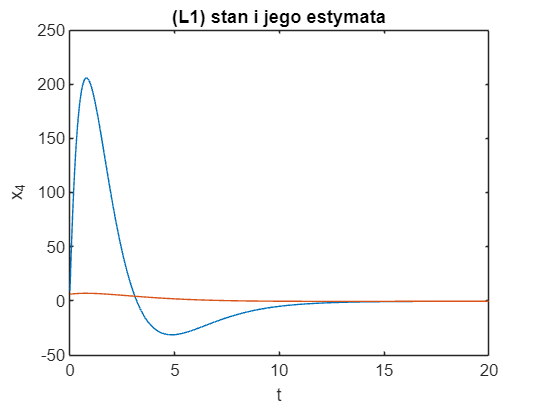


% badanie symulacyjne układu szeregowego systemu i obserwatora stanu
% systemu
[y_1, Tout1, x_1]=lsim(systemIobserwator1, u_sin, T_sin, wp);
[y_2, Tout2, x_2]=lsim(systemIobserwator2, u_sin, T_sin, wp);
[y_3, Tout3, x_3]=lsim(systemIobserwator3, u_sin, T_sin, wp);

for i=1:n
    f1{i}=figure(i);
    plot(Tout1, (x_1(:,[i,n+i]))' )
    xlabel('t'), ylabel(['x_', int2str(i)]), title('(L1) stan i jego estymata')
end

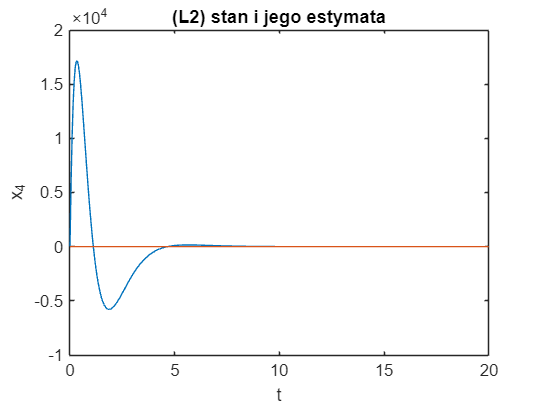


for i=1:n
    f2{i}=figure(i);
    plot(Tout2, (x_2(:,[i,n+i]))' )
    xlabel('t'), ylabel(['x_', int2str(i)]), title('(L2) stan i jego estymata')
end

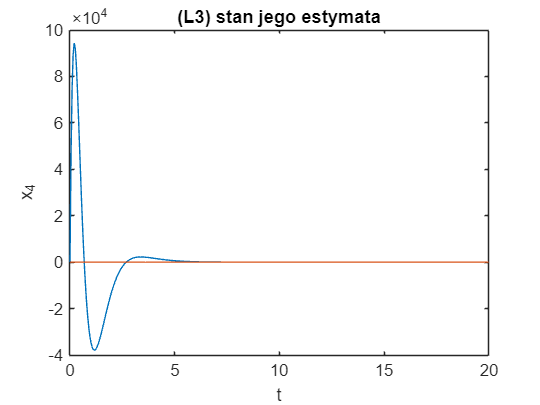


for i=1:n
    f3{i}=figure(i);
    plot(Tout3, (x_3(:,[i,n+i]))' )
    xlabel('t'), ylabel(['x_', int2str(i)]), title('(L3) stan jego estymata')
end


if all(abs(sort(eig(obserwatorLuenbergera1.A))' - A_lz_wartosci_wlasne*0.5  ) < 1e-6) && ...
   all(abs(sort(eig(obserwatorLuenbergera2.A))' - A_lz_wartosci_wlasne      ) < 1e-6) && ...
   all(abs(sort(eig(obserwatorLuenbergera3.A))' - A_lz_wartosci_wlasne*1.5  ) < 1e-6)
    disp(':)')
else
    disp(':(')
end

:(


Powtórzyć powyższe zadanie dla różnych wartości $n \geq 2$. Odpowiedzieć na pytanie jaki jest wpływ położenia $\lambda_{z,i}$ względem osi urojonej na amplitudę i prędkość zbieżności zmiennych $\hat{x}(t)$ do $x(t)$?

**Odp.**: 

Szybkość zbieżności układu zależy od odległości biegunów od osi urojonej w lewo — im dalej bieguny znajdują się od osi urojonej, tym szybciej układ zbiega do stanu równowagi.

Amplituda oscylacji jest większa, gdy bieguny są bliżej osi urojonej, a maleje, gdy bieguny przesuwają się dalej w lewo. Im mniejsze wartości rzeczywiste biegunów, tym szybciej oscylacje wygasają.

Te same wyniki dla n =4.